# **Graph Analysis of Air Transport Network**

#### **Packages importation**

import numpy.* 
import pandas.*
import networkx.*
import matplotlib.pyplot.*
import Basemap.* 

clear all 
clc

**Data Importation**

GeoData = readtable("Airports.csv");
GeoData = sortrows(GeoData);
% FlightData = readtable("FlightData.xlsx",'Sheet','2010-2016');
FlightData = readtable("FlightData.xlsx",'Sheet','2003-2009');

####  Visualization of airports for each country (ExtractLocation function)

This function creates a specific dataset extraction for each country, and calculate the airports locations for each of them. 

[USAData, USALat, USALong] = ExtractLocation('United States', GeoData);
[ChinaData, ChinaLat, ChinaLong] = ExtractLocation('China', GeoData);
[UKData, UKLat, UKLong] = ExtractLocation('United Kingdom', GeoData);
[AustraliaData, AustraliaLat, AustraliaLong] = ExtractLocation('Australia', GeoData);

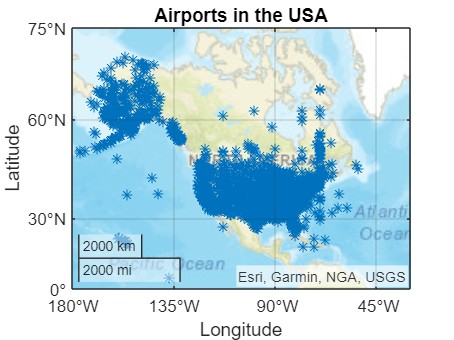

figure,
geoplot(USALat,USALong,'*')
geolimits([0 75],[-160 -50]) % USA 
title 'Airports in the USA';
geobasemap streets 

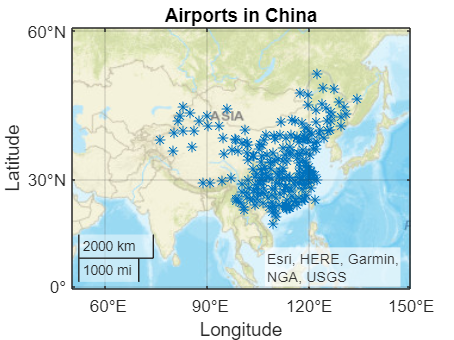


figure,
geoplot(ChinaLat,ChinaLong,'*')
geolimits([0 60],[50 150]) % China 
title 'Airports in China';
geobasemap streets 

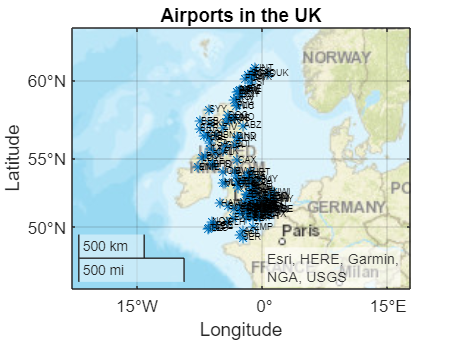


figure,
geoplot(UKLat,UKLong,'*')
hold on
for i = 1:length(UKLat)
    text(UKLat(i), UKLong(i), UKData.id(i), 'FontSize', 5);
end 
hold on
geolimits([45 63],[-15 10]) % UK 
title 'Airports in the UK';
geobasemap streets 

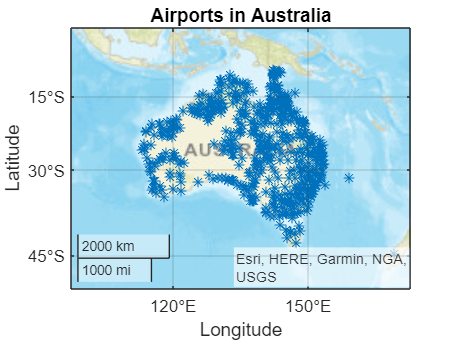


figure,
geoplot(AustraliaLat,AustraliaLong,'*')
geolimits([-50 0],[120 150]) % Australia 
title 'Airports in Australia';
geobasemap streets 

#### Cleaning of the data before getting the sources and targets positions : 

- Delete the sources and targets which don't have their positions in GeoData

[USASource, USATarget, USAWeights, USALines] = cleaning('USA', FlightData, USAData);
[ChinaSource, ChinaTarget, ChinaWeights, ChinaLines] = cleaning('China', FlightData, ChinaData);
[UKSource, UKTarget, UKWeights, UKLines] = cleaning('United Kingdom', FlightData, UKData);
[AustraliaSource, AustraliaTarget, AustraliaWeights, AustraliaLines] = cleaning('Australia', FlightData, AustraliaData);

#### Plot Directed Graph

G_USA = digraph(USASource, USATarget, USAWeights);
G_China = digraph(ChinaSource, ChinaTarget, ChinaWeights);
G_UK = digraph(UKSource, UKTarget, UKWeights);
G_Australia = digraph(AustraliaSource, AustraliaTarget, AustraliaWeights);

#### Distances between nodes

distance_USA = distance_country(G_USA)

distance_USA =            0         184         432         328        2280        1746        1887        2076        1735        1989        2268        2430        2304        2400        1887        1884        2448        2265        1999        1602        2367        2097        2511        2118        1959        1968        2265        2166        2031        2257        1890        2160        1818        1659        1908        2409        2952        2340        2331        1995        2232        1989        2160        2133        2037        2367        2071        1959        2916        2331
          40           0         248         144        2320        1786        1927        2116        1775        2029        2308        2470        2344        2440        1927        1924        2488        2305        2039        1642        2407        2137        2551        2158        1999        2008        2305        2206        2071        2297        1930        2200

distance_China = distance_country(G_China)

distance_China =            0         650         890        1300        1463        2262         512        1504         712        1422        1189         901         991         812        1016        1384        1674        1204         640        2038        1307        4556        1476         980         632        4390        4680         943         836         946         746        1071         752         788        4015        4666        2867        1354        1091         812         670         768         815        1129         858        1430        2944         788         874        1475
         650           0         719         650         813        1612         597         923         730        1251         539         700         341         162         390         734        1024         554         469        1916         657        4574         916         330         461        4475        4698         293         324         365         565         4

distance_UK = distance_country(G_UK)

distance_UK =            0         396        1160        1088        1160        1542        2370        1232         396        1134         846        1462         624         936        1248         809         624         772        1089         312        1326         742         624         824        1304         624        1297        1585        1312         312         616         624        1836         624         624        1024        3078        1266        1571        1628         624        1638         825        5037        7845        1644        2358        3081        6705        6483
         558           0        1628        1556        1628        1585        2413        1700         954         738         889        2020        1182        1404        1451         852         667         815        1647         870        1549         785        1182         867        1862        1182        1765        2143        1667         870        1174        1182 

distance_Australia = distance_country(G_Australia)

distance_Australia =            0          76         346         356         320         460        1400        2879         140         500        1929         916         896        2156         824         788         356        1436        2558        2232        1756         284        4764        3700        4820        1238        1456        1012        1184       13631        1621        1531        1531        1531        1607        1556        1296        2762        1242         759        1555        1222         814         148         814        1147         851         556         889         481
          76           0         270         432         396         536        1476        2955         216         576        2005         992         972        2232         900         864         432        1512        2634        2308        1832         360        4840        3776        4896        1314        1532        1088        1260       13707        1697      


writematrix(distance_USA,'distance_USA');
writematrix(distance_China,'distance_China');
writematrix(distance_UK,'distance_UK');
writematrix(distance_Australia,'distance_Australia');

writematrix(UKLatSource,'UKLatSource');
writematrix(UKLongSource,'UKLongSource');
writematrix(UKLatTarget,'UKLatTarget');
writematrix(UKLongTarget,'UKLongTarget');

writematrix(USALatSource,'USALatSource');
writematrix(USALongSource,'USALongSource');
writematrix(USALatTarget,'USALatTarget');
writematrix(USALongTarget,'USALongTarget');

figure,
nodes = unique(USATarget)

nodes = 642×1 cell array
    {'ABE'}
    {'ABI'}
    {'ABL'}
    {'ABQ'}
    {'ABR'}
    {'ABY'}
    {'ACK'}
    {'ACT'}
    {'ACV'}
    {'ACY'}
    {'ADK'}
    {'ADQ'}
    {'AET'}
    {'AEX'}
    {'AGN'}
    {'AGS'}
    {'AHN'}
    {'AIA'}
    {'AIN'}
    {'AKB'}
    {'AKI'}
    {'AKK'}
    {'AKN'}
    {'AKP'}
    {'ALB'}
    {'ALO'}
    {'ALS'}
    {'ALW'}
    {'ALZ'}
    {'AMA'}


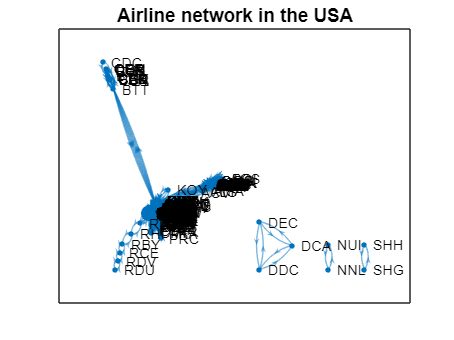

plot(G_USA,'NodeLabel', nodes);
title('Airline network in the USA')


figure,
nodes = unique(ChinaTarget)

nodes = 150×1 cell array
    {'AAT'}
    {'ACX'}
    {'AEB'}
    {'AKA'}
    {'AKU'}
    {'AQG'}
    {'BAV'}
    {'BHY'}
    {'BPX'}
    {'BSD'}
    {'CAN'}
    {'CGD'}
    {'CGO'}
    {'CGQ'}
    {'CHG'}
    {'CIF'}
    {'CIH'}
    {'CKG'}
    {'CSX'}
    {'CTU'}
    {'CZX'}
    {'DAT'}
    {'DAX'}
    {'DDG'}
    {'DIG'}
    {'DLC'}
    {'DLU'}
    {'DNH'}
    {'DOY'}
    {'DSN'}


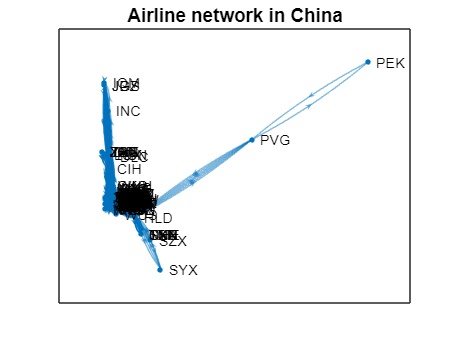

plot(G_China,'NodeLabel', nodes);
title('Airline network in China')


figure,
nodes = unique(UKTarget)

nodes = 64×1 cell array
    {'ABZ'}
    {'ACI'}
    {'BEB'}
    {'BFS'}
    {'BHD'}
    {'BHX'}
    {'BLK'}
    {'BOH'}
    {'BRR'}
    {'BRS'}
    {'CAL'}
    {'CEG'}
    {'COL'}
    {'CSA'}
    {'CWL'}
    {'DND'}
    {'DSA'}
    {'EDI'}
    {'EMA'}
    {'EOI'}
    {'EXT'}
    {'FZO'}
    {'GCI'}
    {'GLA'}
    {'GLO'}
    {'HUY'}
    {'ILY'}
    {'INV'}
    {'IOM'}
    {'ISC'}


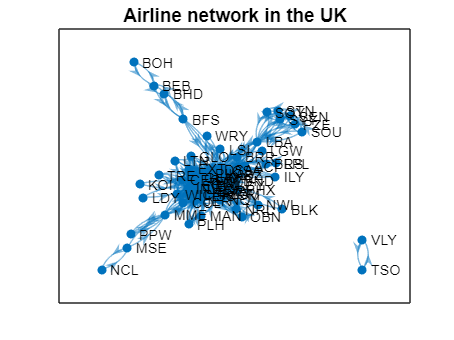

plot(G_UK,'NodeLabel', nodes);
title('Airline network in the UK')


figure,
nodes = unique(AustraliaTarget)

nodes = 119×1 cell array
    {'ABM'}
    {'ABX'}
    {'ADL'}
    {'ALH'}
    {'ARM'}
    {'ASP'}
    {'AUU'}
    {'AVV'}
    {'AYQ'}
    {'BCI'}
    {'BDB'}
    {'BEU'}
    {'BHQ'}
    {'BHS'}
    {'BKQ'}
    {'BLT'}
    {'BME'}
    {'BNE'}
    {'BNK'}
    {'BQL'}
    {'BUC'}
    {'BVI'}
    {'BWT'}
    {'CBR'}
    {'CED'}
    {'CFS'}
    {'CMA'}
    {'CNJ'}
    {'CNS'}
    {'CPD'}


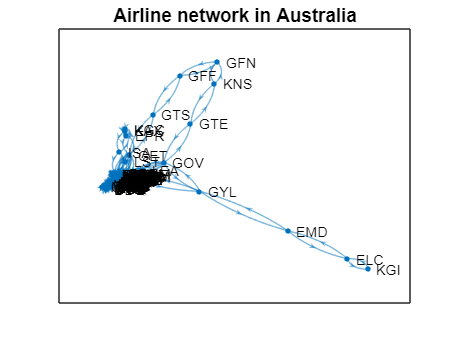

plot(G_Australia,'NodeLabel', nodes);
title('Airline network in Australia')


% figure,
% nodes = unique(USATarget)
% plot(G_USA,'EdgeLabel',G_USA.Edges.Weight);
% title('Airports connections Network in the USA (with weights labels)')

Largest connected component subgraph (for the USA)

[bin_max,binsize_max] = conncomp(G_USA)

bin_max =      4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4


binsize_max =      2     2     3   635


idx_max = binsize_max(bin_max) == max(binsize_max);
SG_max = subgraph(G_USA, idx_max);

figure,
un = unique(USATarget)

un = 642×1 cell array
    {'ABE'}
    {'ABI'}
    {'ABL'}
    {'ABQ'}
    {'ABR'}
    {'ABY'}
    {'ACK'}
    {'ACT'}
    {'ACV'}
    {'ACY'}
    {'ADK'}
    {'ADQ'}
    {'AET'}
    {'AEX'}
    {'AGN'}
    {'AGS'}
    {'AHN'}
    {'AIA'}
    {'AIN'}
    {'AKB'}
    {'AKI'}
    {'AKK'}
    {'AKN'}
    {'AKP'}
    {'ALB'}
    {'ALO'}
    {'ALS'}
    {'ALW'}
    {'ALZ'}
    {'AMA'}


nodes_max = un(idx_max)

nodes_max = 635×1 cell array
    {'ABE'}
    {'ABI'}
    {'ABL'}
    {'ABQ'}
    {'ABR'}
    {'ABY'}
    {'ACK'}
    {'ACT'}
    {'ACV'}
    {'ACY'}
    {'ADK'}
    {'ADQ'}
    {'AET'}
    {'AEX'}
    {'AGN'}
    {'AGS'}
    {'AHN'}
    {'AIA'}
    {'AIN'}
    {'AKB'}
    {'AKI'}
    {'AKK'}
    {'AKN'}
    {'AKP'}
    {'ALB'}
    {'ALO'}
    {'ALS'}
    {'ALW'}
    {'ALZ'}
    {'AMA'}



h_max = plot(SG_max,'NodeLabel', nodes_max)

h_max =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 2
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {1×635 cell}
     EdgeLabel: {}
         XData: [0.1324 0.1394 0.1394 0.1463 2.9697 2.8735 1.0160 1.0999 2.1343 2.8857 3.4559 0.3206 0.3148 0.1577 0.1561 3.5721 0.4221 1.1838 0.1625 0.2515 0.5016 0.4556 3.0671 2.9237 0.1810 0.1692 2.6074 1.0912 0.2969 2.7168 0.3873 0.3607 3.0780 … ]
         YData: [-0.3528 -0.4760 -0.4760 -0.5992 1.0567 1.0681 0.3942 0.3247 0.7668 1.0657 1.1687 0.0078 -0.1322 -0.1190 -0.1666 1.3341 -0.0185 0.2552 -0.2344 0.2480 -0.0257 -0.0205 1.1213 1.0810 -0.3045 -0.1260 0.8184 0.3132 -0.0132 0.8674 0.0395 … ]
         ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 

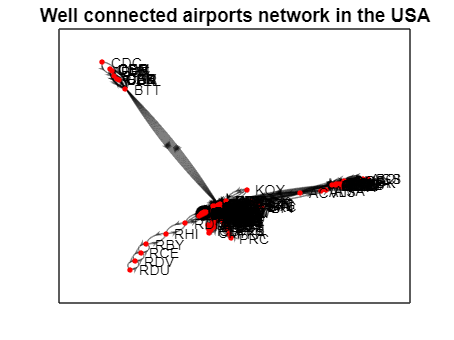

h_max.NodeColor = 'r';
h_max.EdgeColor = 'black';

title('Well connected airports network in the USA')

Smallest connected component subgraph (for the USA)

[bin_min,binsize_min] = conncomp(G_USA)

bin_min =      4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4


binsize_min =      2     2     3   635


idx_min = binsize_min(bin_min) == min(binsize_min);
SG_min = subgraph(G_USA, idx_min);

figure,
nodes_min = un(idx_min)

nodes_min = 4×1 cell array
    {'NNL'}
    {'NUI'}
    {'SHG'}
    {'SHH'}



h_min = plot(SG_min,'NodeLabel', nodes_min)

h_min =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'NNL'  'NUI'  'SHG'  'SHH'}
     EdgeLabel: {}
         XData: [0.5000 0.5000 0.5000 0.5000]
         YData: [0.1500 1.1500 1.4500 2.4500]
         ZData: [0 0 0 0]

  Show all properties


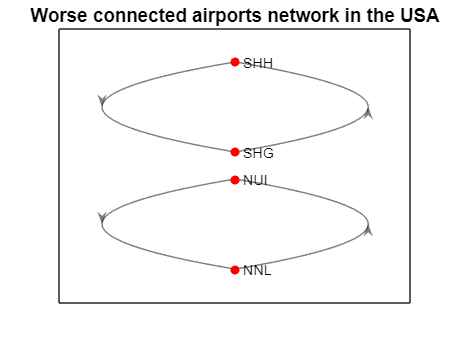

h_min.NodeColor = 'r';
h_min.EdgeColor = 'black';

title('Worse connected airports network in the USA')

Medium connected component subgraph

[bin_av,binsize_av] = conncomp(G_USA)

bin_av =      4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4


binsize_av =      2     2     3   635


idx_av = binsize_av(bin_av) == 3;
SG_av = subgraph(G_USA, idx_av);

figure,
nodes_av = un(idx_av)

nodes_av = 3×1 cell array
    {'DCA'}
    {'DDC'}
    {'DEC'}



h_avg = plot(SG_av,'NodeLabel', nodes_av)

h_avg =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'DCA'  'DDC'  'DEC'}
     EdgeLabel: {}
         XData: [0.7768 0.2843 -1.0612]
         YData: [0.7768 -1.0612 0.2843]
         ZData: [0 0 0]

  Show all properties


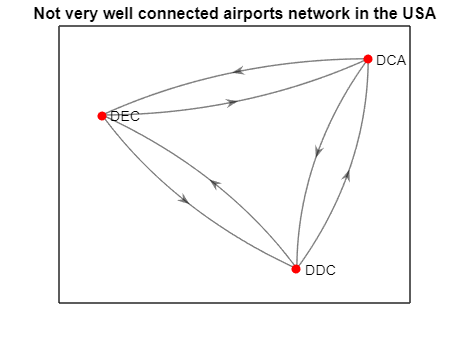

h_avg.NodeColor = 'r';
h_avg.EdgeColor = 'black';

title('Not very well connected airports network in the USA', 'FontSize',9)

Table with the degree corresponding to each node

TableDegreeUSA = TableDegree(G_USA);
TableDegreeChina = TableDegree(G_China);
TableDegreeUK = TableDegree(G_UK);
TableDegreeAustralia = TableDegree(G_Australia);

#### Airports Network Visualization  

% Positions of airports for sources and targets of the lines 
[USALatSource, USALongSource, USALatTarget, USALongTarget] = PositionsLines(USASource, USATarget, USAData)

USALatSource =    59.6429
   59.4500
   59.3500
   59.3667
   59.4500
   61.0000
   61.5787
   61.5787
   60.7833
   60.7833


USALongSource =  -151.5483
 -151.7000
 -151.8333
 -151.9167
 -151.7000
 -162.7500
 -159.5222
 -159.5222
 -161.8333
 -161.8333


USALatTarget =    59.4500
   59.6429
   59.6429
   59.3500
   59.3667
   60.7833
   61.6667
   62.0500
   60.2167
   61.9333


USALongTarget =  -151.7000
 -151.5483
 -151.5483
 -151.8333
 -151.9167
 -161.8333
 -159.2500
 -163.1833
 -162.0167
 -162.8833


[ChinaLatSource, ChinaLongSource, ChinaLatTarget, ChinaLongTarget] = PositionsLines(ChinaSource, ChinaTarget, ChinaData)

ChinaLatSource =    43.8650
   43.8650
   29.5650
   29.5650
   29.5650
   29.5650
   30.6700
   30.6700
   34.7550
   23.1450


ChinaLongSource =   125.3400
  125.3400
  106.5950
  106.5950
  106.5950
  106.5950
  104.0700
  104.0700
  113.6651
  113.3250


ChinaLatTarget =    34.2800
   36.6750
   38.4680
   29.1333
   30.2500
   36.0167
   18.2591
   36.6750
   41.8717
   30.6700


ChinaLongTarget =   117.1800
  116.9950
  106.2730
  110.4833
  120.1700
  103.7500
  109.5040
  116.9950
  123.4333
  104.0700


[UKLatSource, UKLongSource, UKLatTarget, UKLongTarget] = PositionsLines(UKSource, UKTarget, UKData)

UKLatSource =    57.4671
   58.2167
   56.5833
   56.5000
   56.6167
   56.5000
   51.4000
   53.2700
   56.0589
   57.4671


UKLongSource =    -4.2333
   -6.3333
   -5.5000
   -6.9167
   -6.6167
   -6.9167
   -3.3500
   -4.4300
   -6.2439
   -4.2333


UKLatTarget =    58.2167
   57.4671
   56.5000
   56.5833
   56.5000
   56.6167
   53.2700
   51.4000
   56.5833
   59.8789


UKLongTarget =    -6.3333
   -4.2333
   -6.9167
   -5.5000
   -6.9167
   -6.6167
   -4.4300
   -3.3500
   -5.5000
   -1.2956


[AustraliaLatSource, AustraliaLongSource, AustraliaLatTarget, AustraliaLongTarget] = PositionsLines(AustraliaSource, AustraliaTarget, AustraliaData)

AustraliaLatSource =   -16.8878
  -14.0000
  -12.4167
  -14.0000
  -27.4550
  -16.8878
  -27.4550
  -16.8878
  -34.9450
  -27.4550


AustraliaLongSource =   145.7633
  136.5000
  130.8667
  136.5000
  153.0351
  145.7633
  153.0351
  145.7633
  138.5306
  153.0351


AustraliaLatTarget =   -14.0000
  -16.8878
  -14.0000
  -12.4167
  -16.8878
  -27.4550
  -16.8878
  -27.4550
  -37.6733
  -12.4167


AustraliaLongTarget =   136.5000
  145.7633
  136.5000
  130.8667
  145.7633
  153.0351
  145.7633
  153.0351
  144.8433
  130.8667


AUSTRALIA

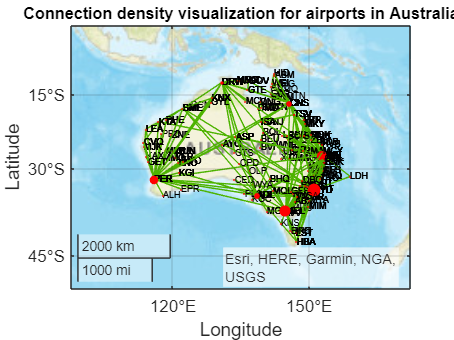

figure,
for i = 1:size(AustraliaLatSource,1)
    geoplot([AustraliaLatSource(i) AustraliaLatTarget(i)],[AustraliaLongSource(i) AustraliaLongTarget(i)],'-','Color',[0.3 0.7 0]);
    
    text(AustraliaLatSource(i), AustraliaLongSource(i), AustraliaSource(i), 'FontSize', 5)
    text(AustraliaLatTarget(i), AustraliaLongTarget(i), AustraliaTarget(i), 'FontSize', 5)

    Size1 = table2array(TableDegreeAustralia(strcmp(TableDegreeAustralia.Name, AustraliaSource(i)),2)); % Size corresponding to the node degree
    Size2 = table2array(TableDegreeAustralia(strcmp(TableDegreeAustralia.Name, AustraliaTarget(i)),2)); % Size corresponding to the node degree

    geoplot(AustraliaLatSource(i),AustraliaLongSource(i),'.','Color','r','MarkerSize',Size1/10)
    geoplot(AustraliaLatTarget(i),AustraliaLongTarget(i),'.','Color','r','MarkerSize',Size2/10)

    hold on
end
hold on
geolimits([-50 0],[120 150]) % Australia
title ('Connection density visualization for airports in Australia', 'FontSize', 9);
geobasemap streets 

UK

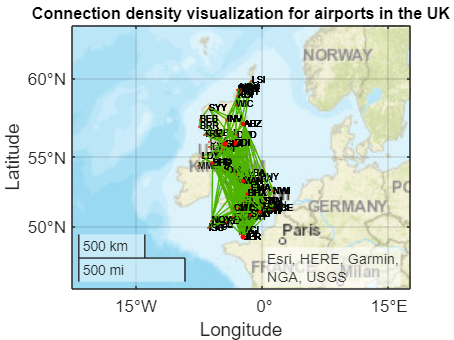

figure,
for i = 1:size(UKLatSource,1)
    geoplot([UKLatSource(i) UKLatTarget(i)],[UKLongSource(i) UKLongTarget(i)],'-','Color',[0.3 0.7 0]);
    
    text(UKLatSource(i), UKLongSource(i), UKSource(i), 'FontSize', 5)
    text(UKLatTarget(i), UKLongTarget(i), UKTarget(i), 'FontSize', 5)

    Size1 = table2array(TableDegreeUK(strcmp(TableDegreeUK.Name, UKSource(i)),2)); % Size corresponding to the node degree
    Size2 = table2array(TableDegreeUK(strcmp(TableDegreeUK.Name, UKTarget(i)),2)); % Size corresponding to the node degree

    geoplot(UKLatSource(i),UKLongSource(i),'.','Color','r','MarkerSize',Size1/10)
    geoplot(UKLatTarget(i),UKLongTarget(i),'.','Color','r','MarkerSize',Size2/10)

    hold on
end
hold on
geolimits([45 63],[-15 10]) % UK
title ('Connection density visualization for airports in the UK', 'FontSize', 9);
geobasemap streets 

USA

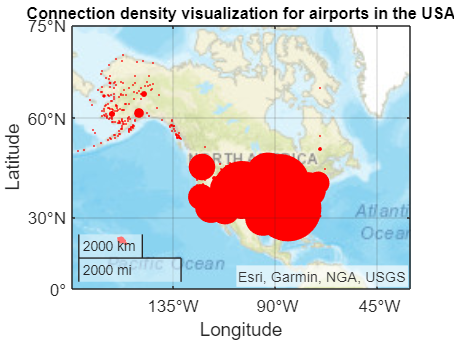

figure,
for i = 1:size(USALatSource,1)
    % geoplot([USALatSource(i) USALatTarget(i)],[USALongSource(i) USALongTarget(i)],'-','Color',[0.3 0.7 0],'LineWidth', USAWeights1(i)/10000)
      
    % text(USALatSource(i), USALongSource(i), USASource(i), 'FontSize', 5)
    % text(USALatTarget(i), USALongTarget(i), USATarget(i), 'FontSize', 5)

    Size1 = table2array(TableDegreeUSA(strcmp(TableDegreeUSA.Name, USASource(i)),2)); % Size corresponding to the node degree
    Size2 = table2array(TableDegreeUSA(strcmp(TableDegreeUSA.Name, USATarget(i)),2)); % Size corresponding to the node degree

    geoplot(USALatSource(i),USALongSource(i),'.','Color','r','MarkerSize',Size1/10)
    geoplot(USALatTarget(i),USALongTarget(i),'.','Color','r','MarkerSize',Size2/10)

    hold on
end
hold on
geolimits([0 75],[-160 -50]) % USA
title ('Connection density visualization for airports in the USA', 'FontSize', 9);
geobasemap streets 

China

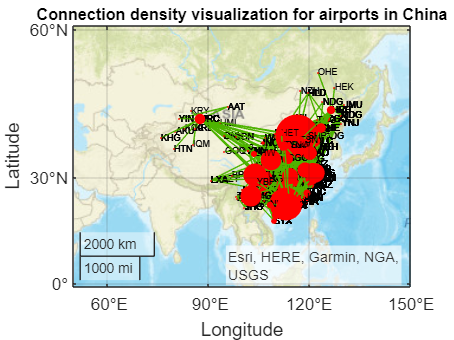

figure,
for i = 1:size(ChinaLatSource,1)
    geoplot([ChinaLatSource(i) ChinaLatTarget(i)],[ChinaLongSource(i) ChinaLongTarget(i)],'-','Color',[0.3 0.7 0]);
    
    text(ChinaLatSource(i), ChinaLongSource(i), ChinaSource(i), 'FontSize', 5)
    text(ChinaLatTarget(i), ChinaLongTarget(i), ChinaTarget(i), 'FontSize', 5)

    Size1 = table2array(TableDegreeChina(strcmp(TableDegreeChina.Name, ChinaSource(i)),2)); % Size corresponding to the node degree
    Size2 = table2array(TableDegreeChina(strcmp(TableDegreeChina.Name, ChinaTarget(i)),2)); % Size corresponding to the node degree

    geoplot(ChinaLatSource(i),ChinaLongSource(i),'.','Color','r','MarkerSize',Size1/10)
    geoplot(ChinaLatTarget(i),ChinaLongTarget(i),'.','Color','r','MarkerSize',Size2/10)

    hold on
end
hold on
geolimits([0 60],[50 150]) % China
title ('Connection density visualization for airports in China', 'FontSize', 9);
geobasemap streets 

#### Weighted Degree Distribution

[y1, rank1, weights1, rsq1, p1] = W 

y1 =     5.1438
    5.1399
    5.1359
    5.1320
    5.1280
    5.1241
    5.1201
    5.1162
    5.1122
    5.1083


rank1 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


weights1 =     6.9234
    6.7848
    6.7419
    6.7411
    6.6813
    6.6121
    6.5923
    6.5731
    6.5439
    6.5341


rsq1 = 0.8320

p1 =    -0.0040    5.1478


[y2, rank2, weights2, rsq2, p2] = WDD(G_China, 50, 100);
[y3, rank3, weights3, rsq3, p3] = WDD(G_UK, 20, 40); 
[y4, rank4, weights4, rsq4, p4] = WDD(G_Australia, 40, 80); 

USA

figure,
plot(weights1);
hold on
plot(rank1,y1);
xlim([0 700]);
xlabel('Rank');
ylabel('Weighted Degree (log scale)');
txt = {'b', round(p1(1),3)}, 

txt = 1×2 cell array
    {'b'}    {[-0.0040]}


text(100,2,txt,'Color','blue','FontSize',13);
txt2 = {'R^2', round(rsq1,3)}, 

txt2 = 1×2 cell array
    {'R^2'}    {[0.8320]}


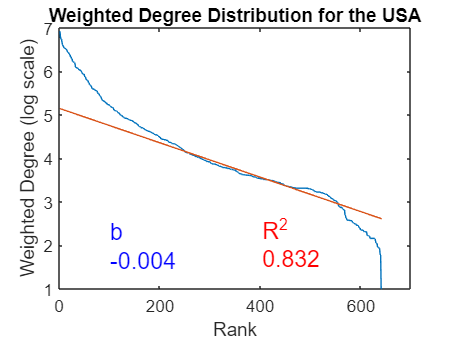

text(400,2,txt2,'Color','red','FontSize',13);
title('Weighted Degree Distribution for the USA');

CHINA

figure,
plot(weights2);
hold on
plot(rank2,y2);
xlabel('Rank');
ylabel('Weighted Degree (log scale)');
xlim([0 160]);
txt = {'b', round(p2(1),3)}, 

txt = 1×2 cell array
    {'b'}    {[-0.0150]}


text(20,3,txt,'Color','blue','FontSize',13);
txt2 = {'R^2', round(rsq2,3)}, 

txt2 = 1×2 cell array
    {'R^2'}    {[0.8940]}


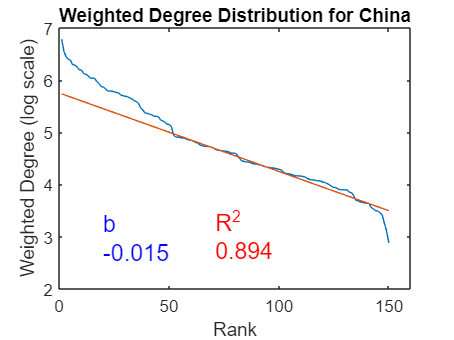

text(70,3,txt2,'Color','red','FontSize',13);
title('Weighted Degree Distribution for China');

UK

figure,
plot(weights3);
hold on
plot(rank3,y3);
xlabel('Rank');
ylabel('Weighted Degree (log scale)');
xlim([0 70]);
txt = {'b', round(p3(1),3)}, 

txt = 1×2 cell array
    {'b'}    {[-0.0590]}


text(10,3,txt,'Color','blue','FontSize',13);
txt2 = {'R^2', round(rsq3,3)}, 

txt2 = 1×2 cell array
    {'R^2'}    {[0.9700]}


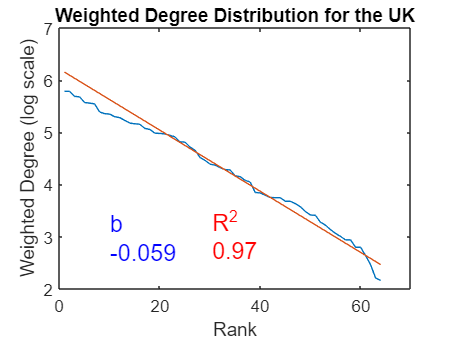

text(30,3,txt2,'Color','red','FontSize',13);
title('Weighted Degree Distribution for the UK');

AUSTRALIA

figure,
plot(weights4);
hold on
plot(rank4,y4);
xlabel('Rank');
ylabel('Weighted Degree (log scale)');
xlim([0 130]);
txt = {'b', round(p4(1),3)}, 

txt = 1×2 cell array
    {'b'}    {[-0.0180]}


text(10,3,txt,'Color','blue','FontSize',13);
txt2 = {'R^2', round(rsq4,3)}, 

txt2 = 1×2 cell array
    {'R^2'}    {[0.8460]}


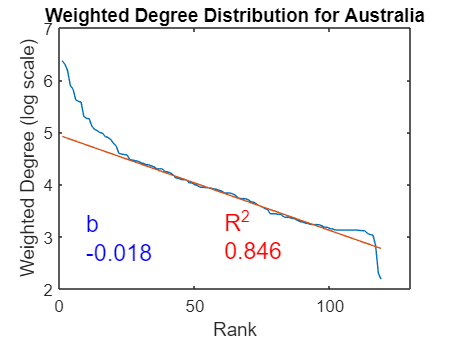

text(60,3,txt2,'Color','red','FontSize',13);
title('Weighted Degree Distribution for Australia');

#### Weighted Degree Cumulative Distribution

[Dwz_USA, C_USA] = WDCD(TableDegreeUSA, G_USA);
[Dwz_China, C_China] = WDCD(TableDegreeChina, G_China);
[Dwz_UK, C_UK] = WDCD(TableDegreeUK, G_UK);
[Dwz_Australia, C_Australia] = WDCD(TableDegreeAustralia, G_Australia);

USA

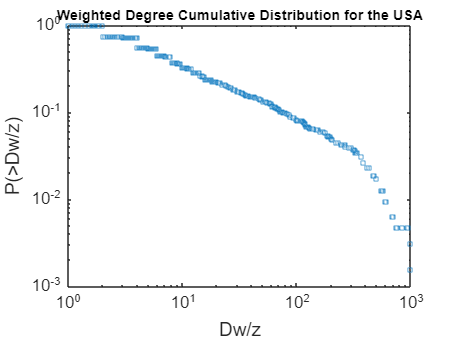

figure,
loglog(Dwz_USA,C_USA,'s','MarkerSize',3); 
xlim([1 1000]);
xlabel('Dw/z')
ylabel('P(>Dw/z)')
title('Weighted Degree Cumulative Distribution for the USA','FontSize',8)

China

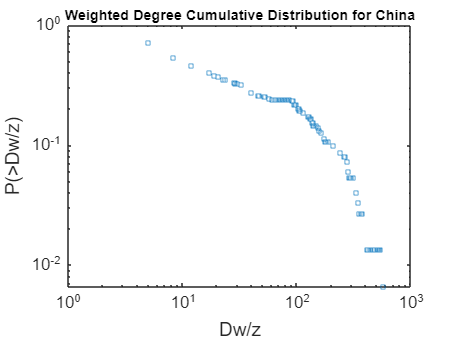

figure,
loglog(Dwz_China,C_China,'s','MarkerSize',3); 
xlim([1 1000]);
xlabel('Dw/z')
ylabel('P(>Dw/z)')
title('Weighted Degree Cumulative Distribution for China','FontSize',8)

UK

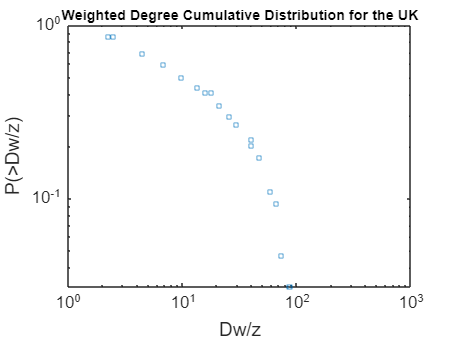

figure,
loglog(Dwz_UK,C_UK,'s','MarkerSize',3); 
xlim([1 1000]);
xlabel('Dw/z')
ylabel('P(>Dw/z)')
title('Weighted Degree Cumulative Distribution for the UK','FontSize',8)

AUSTRALIA

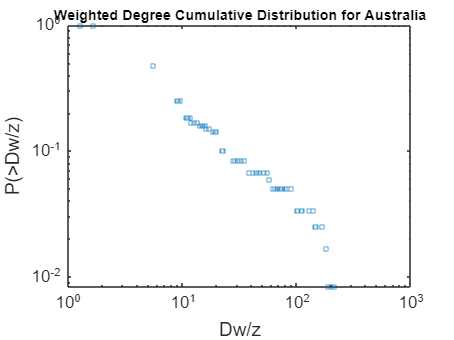

figure,
loglog(Dwz_Australia,C_Australia,'s','MarkerSize',3); 
xlim([1 1000]);
xlabel('Dw/z')
ylabel('P(>Dw/z)')
title('Weighted Degree Cumulative Distribution for Australia','FontSize',8)

#### Assortativity

% Adjacency matrix and Assortativity

Adj_USA = adjacency(G_USA); 
A_USA = assortativity(Adj_USA); % -0.2669

Error using get
Invalid handle

Error in FinalCode>assortativity2 (line 1402)
gp = get(g, 'group');


Adj_China = adjacency(G_China); 
A_China = assortativity(Adj_China); % -0.4409
 
Adj_UK = adjacency(G_UK); 
A_UK = assortativity(Adj_UK); % -0.1390

Adj_Australia = adjacency(G_Australia); 
A_Australia = assortativity(Adj_Australia); % -0.3042

figure,
spy(Adj_USA) % plot the non-zero elements (with 1)
% when there is a point there is a route between both concerned nodes 
% Square core visualization (top left hand corner) : core periphery 
title('Adjacency Matrix for the USA')

figure,
spy(Adj_China) 
title('Adjacency Matrix for China')

figure,
spy(Adj_UK)  
title('Adjacency Matrix for the UK')

figure,
spy(Adj_Australia) 
title('Adjacency Matrix for Australia')

% PAS FINI
% Moyennes des degres voisins 
DegreeUSA = table2array(TableDegreeUSA(:,2));
D = []; % average degree of neighbours (pre and suc) for each node
for k=1:size(G_USA.Nodes,1)
    deg = 0
    pre = array2table(predecessors(G_USA,k));
    suc = array2table(successors(G_USA,k));
    for i=1:size(pre,1)
        deg = deg + indegree(G_USA,table2array(pre(i,1))) + outdegree(G_USA,table2array(pre(i,1)));
    end 
    for i=1:size(suc,1)
        deg = deg + indegree(G_USA,table2array(suc(i,1))) + outdegree(G_USA,table2array(suc(i,1)));
    end 
    deg = deg/(size(pre,1)+size(suc,1));
    D = [D, deg];
end 

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

deg = 0

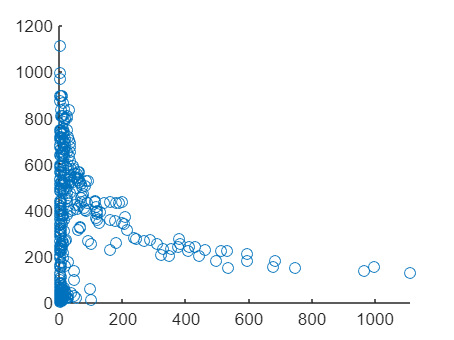


D1 = (reshape(D, [642 1]));
rank1 = (DegreeUSA);
T=table(rank1,D1);
T=sortrows(T,1);
rank = table2array(T(:,1));
D = table2array(T(:,2));

figure,
scatter(rank,D)%,'s','Marker','*','MarkerSize',3);

#### Degree Distribution

figure,
histogram(table2array(TableDegreeUSA(:,2)));                                                                  % restore default
xlabel('Degrees')                                   
ylabel('Number of Nodes')                          
title('Degree Distribution for the USA')                        
txt = {'Assortativity ' round(A_USA,3)}, 

txt = 1×2 cell array
    {'Assortativity '}    {[-0.2910]}


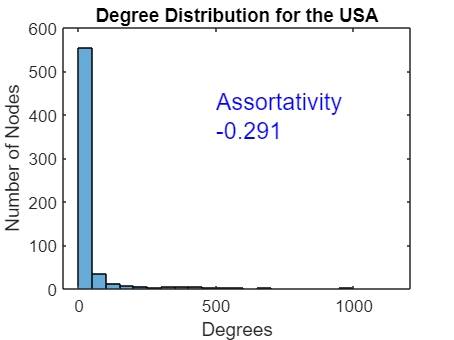

text(500,400,txt,'Color','blue','FontSize',13);


figure,
histogram(table2array(TableDegreeChina(:,2)));                                                                  % restore default
xlabel('Degrees')                                   
ylabel('Number of Nodes')                          
title('Degree Distribution for China')                        
txt = {'Assortativity ' round(A_China,3)}, 

txt = 1×2 cell array
    {'Assortativity '}    {[-0.4050]}


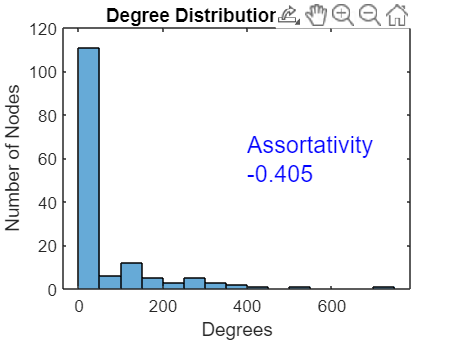

text(400,60,txt,'Color','blue','FontSize',13);


figure,
histogram(table2array(TableDegreeUK(:,2)));                                                                  % restore default
xlabel('Degrees')                                   
ylabel('Number of Nodes')                          
title('Degree Distribution for the UK')                        
txt = {'Assortativity ' round(A_UK,3)}, 

txt = 1×2 cell array
    {'Assortativity '}    {[-0.1320]}


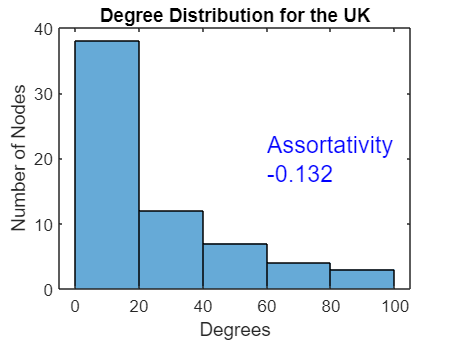

text(60,20,txt,'Color','blue','FontSize',13);


figure,
histogram(table2array(TableDegreeAustralia(:,2)));                                                                  % restore default
xlabel('Degrees')                                   
ylabel('Number of Nodes')                          
title('Degree Distribution for Australia')                        
txt = {'Assortativity ' round(A_Australia,3)}, 

txt = 1×2 cell array
    {'Assortativity '}    {[-0.3510]}


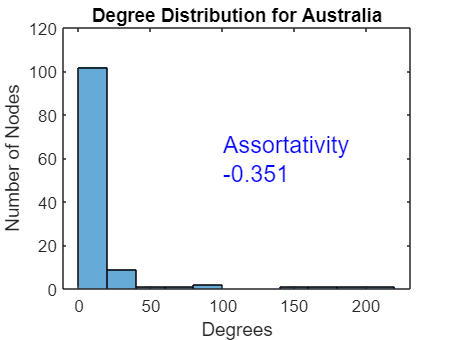

text(100,60,txt,'Color','blue','FontSize',13);

#### Normalized Betweenness VS Normalized Degree

[BC_USA, BC_n_USA, D_USA, D_n_USA] = nbnd(G_USA);
[BC_China, BC_n_China, D_China, D_n_China] = nbnd(G_China);
[BC_UK, BC_n_UK, D_UK, D_n_UK] = nbnd(G_UK);
[BC_Australia, BC_n_Australia, D_Australia, D_n_Australia] = nbnd(G_Australia);

figure,
scatter(BC_n_USA,D_n_USA,30,'.');    
for i=1:size(BC_USA,1)
    text(BC_n_USA(i), D_n_USA(i), table2array(G_USA.Nodes(i,1)),'FontSize',5);
end
xlabel('Normalized Betweenness') 
ylabel('Normalized Degree')                       
title('Normalized Betweenness VS Normalized Degree for the USA','FontSize',8)


figure,
scatter(BC_n_China,D_n_China,30,'.');    
for i=1:size(BC_China,1)
    text(BC_n_China(i), D_n_China(i), table2array(G_China.Nodes(i,1)),'FontSize',5);
end
xlabel('Normalized Betweenness') 
ylabel('Normalized Degree')                       
title('Normalized Betweenness VS Normalized Degree for China','FontSize',8)


figure,
scatter(BC_n_UK,D_n_UK,30,'.');    
for i=1:size(BC_UK,1)
    text(BC_n_UK(i), D_n_UK(i), table2array(G_UK.Nodes(i,1)),'FontSize',5);
end
xlabel('Normalized Betweenness') 
ylabel('Normalized Degree')                       
title('Normalized Betweenness VS Normalized Degree for the UK','FontSize',8)


figure,
scatter(BC_n_Australia,D_n_Australia,30,'.');    
for i=1:size(BC_Australia,1)
    text(BC_n_Australia(i), D_n_Australia(i), table2array(G_Australia.Nodes(i,1)),'FontSize',5);
end
xlabel('Normalized Betweenness') 
ylabel('Normalized Degree')                       
title('Normalized Betweenness VS Normalized Degree for Australia','FontSize',8)

#### Degree VS Betweenness

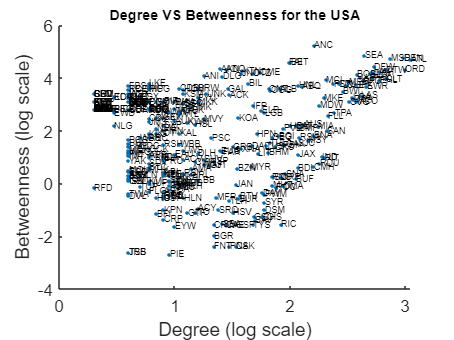

figure,
scatter(log10(D_USA),log10(BC_USA),'.');    
for i=1:size(BC_USA,1)
    text(log10(D_USA(i)),log10(BC_USA(i)), table2array(G_USA.Nodes(i,1)),'FontSize',5);
end
xlabel('Degree (log scale)') 
ylabel('Betweenness (log scale)')                       
title('Degree VS Betweenness for the USA','FontSize',8) 

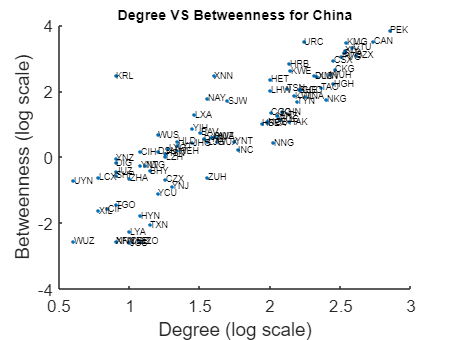


figure,
scatter(log10(D_China),log10(BC_China),'.');    
for i=1:size(BC_China,1)
    text(log10(D_China(i)),log10(BC_China(i)), table2array(G_China.Nodes(i,1)),'FontSize',5);
end
xlabel('Degree (log scale)') 
ylabel('Betweenness (log scale)')                       
title('Degree VS Betweenness for China','FontSize',8) 

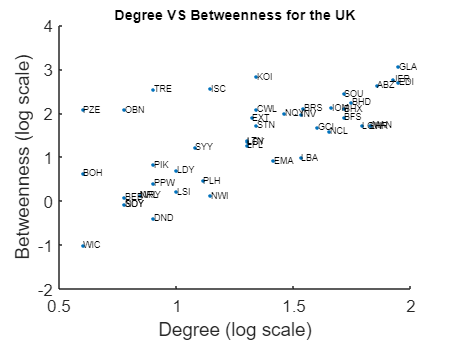


figure,
scatter(log10(D_UK),log10(BC_UK),'.');   
for i=1:size(BC_UK,1)
    text(log10(D_UK(i)),log10(BC_UK(i)), table2array(G_UK.Nodes(i,1)),'FontSize',5);
end
xlabel('Degree (log scale)') 
ylabel('Betweenness (log scale)')                       
title('Degree VS Betweenness for the UK','FontSize',8) 

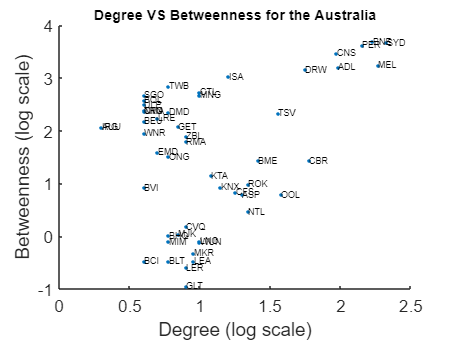


figure,
scatter(log10(D_Australia),log10(BC_Australia),'.');   
for i=1:size(BC_Australia,1)
    text(log10(D_Australia(i)),log10(BC_Australia(i)), table2array(G_Australia.Nodes(i,1)),'FontSize',5);
end
xlabel('Degree (log scale)') 
ylabel('Betweenness (log scale)')                       
title('Degree VS Betweenness for the Australia','FontSize',8) 

#### Communities Detection

- METHOD 1 : Spectral Clustering (Kmeans) : Not very well 

- METHOD 2 : Modularity (best but can't choose K) 

USA 

% DETECTION

Comm2USA=GCModulMax(Adj_USA) % Modularity method

!!! Graph with isolated communities, no more merging possible !!!


Comm2USA =      6
     6
     6
     6
     1
     1
     1
     1
     1
     1


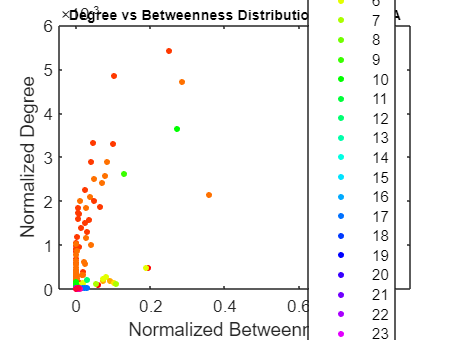

USAclusters = Comm2USA;

% PLOT 1
figure,
gscatter(BC_n_USA,D_n_USA,USAclusters);    
% for i=1:size(BC_USA,1)
%     text(BC_n_USA(i), D_n_USA(i), table2array(G_simp_USA.Nodes(i,1)),'FontSize',5);
% end
xlabel('Normalized Betweenness') 
ylabel('Normalized Degree')                          
title('Degree vs Betweenness Distribution for the USA','FontSize',8) 

% PLOT 2 : HISTOGRAM 
nb = categorical(USAclusters,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30],{'Label 1','Label 2','Label 3','Label 4','Label 5','Label 6','Label 7','Label 8','Label 9','Label 10','Label 11','Label 12','Label 13','Label 14','Label 15','Label 16','Label 17','Label 18','Label 19','Label 20','Label 21','Label 22','Label 23','Label 24','Label 25','Label 26','Label 27','Label 28','Label 29','Label 30'})

nb = 642×1 categorical array
     Label 6 
     Label 6 
     Label 6 
     Label 6 
     Label 1 
     Label 1 
     Label 1 
     Label 1 
     Label 1 
     Label 1 
     Label 1 
     Label 6 
     Label 6 
     Label 6 
     Label 6 
     Label 1 
     Label 6 
     Label 19 
     Label 6 
     Label 6 
     Label 6 
     Label 6 
     Label 1 
     Label 1 
     Label 6 
     Label 6 
     Label 1 
     Label 1 
     Label 6 
     Label 1 


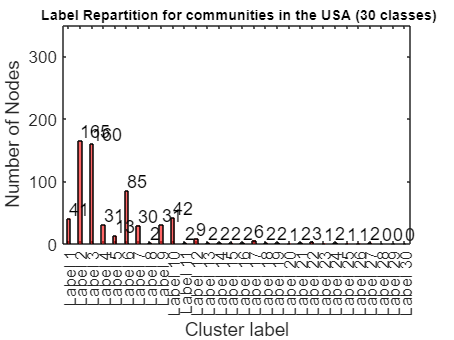

figure,
b=histogram(nb,'BarWidth',0.3,'FaceColor','r');                                                          
xlabel('Cluster label')                                   
ylabel('Number of Nodes')  
ylim([0 350]);
title(' Label Repartition for communities in the USA (30 classes)',FontSize=8)  
y = b.Values;
text(1:b.NumDisplayBins, y+15, string(y));

% PLOT 3 : GRAPH
[indexlabel1USA, indexlabel2USA, indexlabel3USA, LatClass1USA, LongClass1USA, LatClass2USA, LongClass2USA, LatClass3USA, LongClass3USA] = PlotComm(G_USA, USAclusters, USAData);
TableLabel = [G_USA.Nodes, array2table(string(USAclusters))]; % cluster
Table4 = TableLabel(strcmp(TableLabel.Var1, '4'),:); % cluster
Table5 = TableLabel(strcmp(TableLabel.Var1, '5'),:); % cluster
listelabel4 = Table4(:,1); % cluster
listelabel5 = Table5(:,1); % cluster
indexlabel4USA = ind2(table2array(listelabel4), TableLabel); % cluster
indexlabel5USA = ind2(table2array(listelabel5), TableLabel); % cluster
listelabel4.Properties.VariableNames(1) = {'id'} % cluster

listelabel4 = 31×1 table
      id   
    _______

    {'KTN'}
    {'WMK'}
    {'KLW'}
    {'MTM'}
    {'CGA'}
    {'KXA'}
    {'KTB'}
    {'CDV'}
    {'GST'}
    {'JNU'}
    {'WRG'}
    {'SIT'}
    {'YAK'}
    {'PSG'}
    {'TKE'}
    {'ELV'}


listelabel5.Properties.VariableNames(1) = {'id'} % cluster

listelabel5 = 13×1 table
      id   
    _______

    {'ADQ'}
    {'KLN'}
    {'KZB'}
    {'AOS'}
    {'KPR'}
    {'OLH'}
    {'KYK'}
    {'UGI'}
    {'KWP'}
    {'ALZ'}
    {'KPY'}
    {'KMY'}
    {'AKK'}


I4 = innerjoin(listelabel4,USAData); % cluster
I5 = innerjoin(listelabel5,USAData); % cluster
LatClass4USA = table2array(I4(:,{'Lat'})); % cluster
LongClass4USA = table2array(I4(:,{'Lon'}));
LatClass5USA = table2array(I5(:,{'Lat'})); % cluster
LongClass5USA = table2array(I5(:,{'Lon'}));

figure,
h = plot(G_USA)

h =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 2
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {}
     EdgeLabel: {}
         XData: [3.4471 3.4541 3.4541 3.4610 6.2844 6.1881 4.3307 4.4146 5.4490 6.2004 6.7706 3.6353 3.6295 3.4724 3.4708 6.8868 3.7368 4.4985 3.4772 3.5662 3.8163 3.7703 6.3818 6.2384 3.4957 3.4839 5.9221 4.4059 3.6116 6.0315 3.7020 3.6754 6.3927 … ]
         YData: [3.2083 3.0850 3.0850 2.9618 4.6178 4.6291 3.9552 3.8857 4.3278 4.6267 4.7297 3.5688 3.4288 3.4421 3.3944 4.8952 3.5425 3.8162 3.3267 3.8091 3.5354 3.5406 4.6823 4.6421 3.2566 3.4351 4.3795 3.8742 3.5479 4.4284 3.6006 3.5320 4.5628 … ]
         ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 

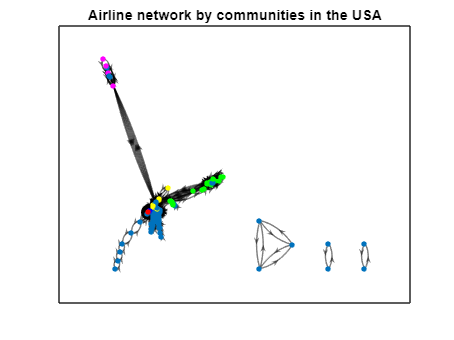

highlight(h,indexlabel1USA,'NodeColor','g')
highlight(h,indexlabel2USA,'NodeColor','r')
highlight(h,indexlabel3USA,'NodeColor','b')
highlight(h,indexlabel4USA,'NodeColor','y')
highlight(h,indexlabel5USA,'NodeColor','m')
h.EdgeColor = 'black';
title('Airline network by communities in the USA','FontSize',8)

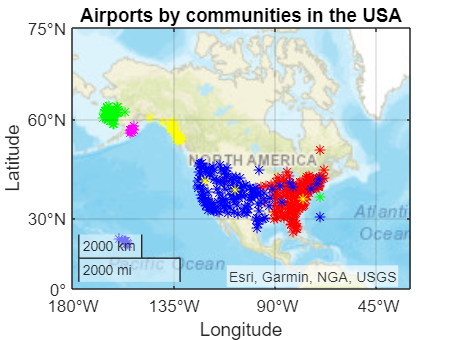


% PLOT 4 : GEOPLOT
figure,
geoplot(LatClass1USA,LongClass1USA,'g*')
hold on
geoplot(LatClass2USA,LongClass2USA,'r*')
geoplot(LatClass3USA,LongClass3USA,'b*')
geoplot(LatClass4USA,LongClass4USA,'y*')
geoplot(LatClass5USA,LongClass5USA,'m*')
geolimits([0 75],[-160 -50]) % USA 
geobasemap streets 
hold off
title('Airports by communities in the USA')

China 

% DETECTION

Comm2China=GCModulMax(Adj_China) % Modularity method

Comm2China =      1
     2
     1
     2
     2
     2
     2
     2
     2
     2


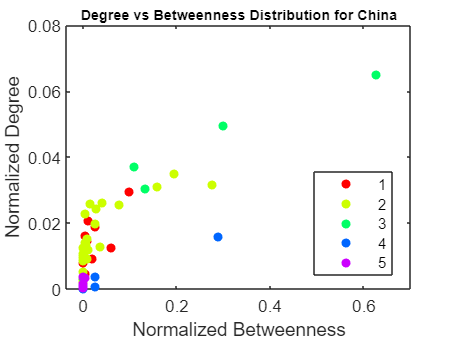

Chinaclusters = Comm2China;

% PLOT 1
figure,
gscatter(BC_n_China,D_n_China,Chinaclusters);    
xlabel('Normalized Betweenness') 
ylabel('Normalized Degree')                          
title('Degree vs Betweenness Distribution for China','FontSize',8) 

% PLOT 2 : HISTOGRAM 
nb = categorical(Chinaclusters,[1 2 3 4 5],{'Label 1','Label 2','Label 3','Label 4','Label 5'})

nb = 150×1 categorical array
     Label 1 
     Label 2 
     Label 1 
     Label 2 
     Label 2 
     Label 2 
     Label 2 
     Label 2 
     Label 2 
     Label 2 
     Label 2 
     Label 1 
     Label 3 
     Label 2 
     Label 2 
     Label 1 
     Label 2 
     Label 3 
     Label 2 
     Label 2 
     Label 2 
     Label 2 
     Label 2 
     Label 2 
     Label 1 
     Label 2 
     Label 2 
     Label 5 
     Label 2 
     Label 2 


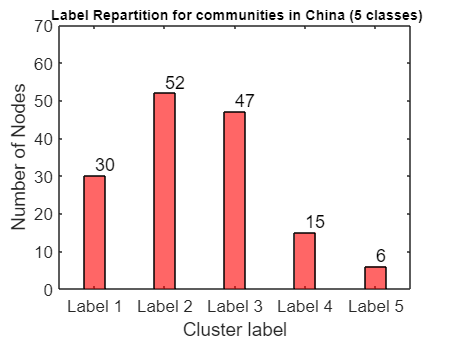

figure,
b=histogram(nb,'BarWidth',0.3,'FaceColor','r');                                                          
xlabel('Cluster label')                                   
ylabel('Number of Nodes')   
ylim([0 70]);
title(' Label Repartition for communities in China (5 classes)',FontSize=8)  
y = b.Values;
text(1:b.NumDisplayBins, y+3, string(y));

% PLOT 3 : GRAPH
[indexlabel1China, indexlabel2China, indexlabel3China, LatClass1China, LongClass1China, LatClass2China, LongClass2China, LatClass3China, LongClass3China] = PlotComm(G_China, Chinaclusters, ChinaData);

figure,
h = plot(G_China)

h =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 2
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {}
     EdgeLabel: {}
         XData: [-0.0106 -0.0350 -0.0018 -0.0075 0.0627 -0.0266 -0.0212 0.0568 -0.0068 -0.0280 -0.0041 -0.0202 -0.0246 -0.0349 -0.0238 0.0101 -0.0617 -0.0674 -0.0019 -0.0354 -0.0270 -0.1031 -0.0011 0.0198 -0.0300 -0.0147 -0.1031 0.0218 -0.0247 0.0122 … ]
         YData: [-0.0378 0.0281 -0.0368 0.0659 -0.0595 -0.0721 -0.0207 -0.0602 0.0315 0.0039 -0.0426 -0.0556 -0.0243 0.0118 -0.0206 -0.1024 0.3579 0.1478 -0.0334 0.0023 0.0240 0.0145 -0.0542 -0.0435 -0.0509 0.5129 0.0145 -0.1026 -0.0127 -0.0120 … ]
         ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 

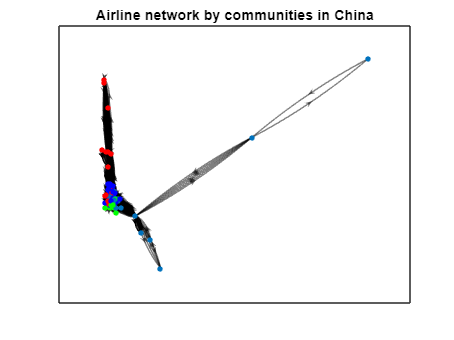

highlight(h,indexlabel1China,'NodeColor','g')
highlight(h,indexlabel2China,'NodeColor','r')
highlight(h,indexlabel3China,'NodeColor','blue')
h.EdgeColor = 'black';
title('Airline network by communities in China','FontSize',8)

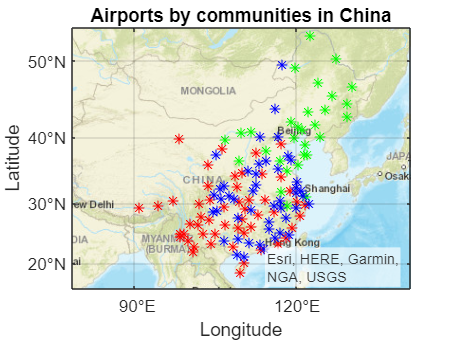


% PLOT 4 : GEOPLOT
figure,
geoplot(LatClass1China,LongClass1China,'g*')
hold on
geoplot(LatClass2China,LongClass2China,'r*')
geoplot(LatClass3China,LongClass3China,'blue*')
geolimits([0 60],[50 150]) % China
geobasemap streets 
hold off
title('Airports by communities in China')

UK

% DETECTION

Comm2UK=GCModulMax(Adj_UK) % Modularity method

!!! Graph with isolated communities, no more merging possible !!!


Comm2UK =      3
     1
     1
     1
     1
     4
     4
     1
     3
     1


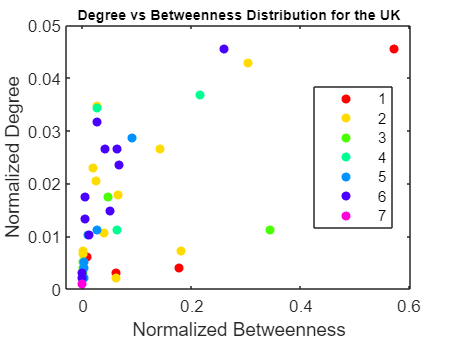

UKclusters = Comm2UK;

% PLOT 1
figure,
gscatter(BC_n_UK,D_n_UK,UKclusters);    
xlabel('Normalized Betweenness') 
ylabel('Normalized Degree')                          
title('Degree vs Betweenness Distribution for the UK','FontSize',8) 

% PLOT 2 : HISTOGRAM 
nb = categorical(UKclusters,[1 2 3 4 5 6 7],{'Label 1','Label 2','Label 3','Label 4','Label 5','Label 6','Label 7'})

nb = 64×1 categorical array
     Label 3 
     Label 1 
     Label 1 
     Label 1 
     Label 1 
     Label 4 
     Label 4 
     Label 1 
     Label 3 
     Label 1 
     Label 6 
     Label 2 
     Label 2 
     Label 1 
     Label 6 
     Label 4 
     Label 4 
     Label 2 
     Label 2 
     Label 2 
     Label 2 
     Label 6 
     Label 5 
     Label 6 
     Label 6 
     Label 6 
     Label 1 
     Label 2 
     Label 5 
     Label 2 


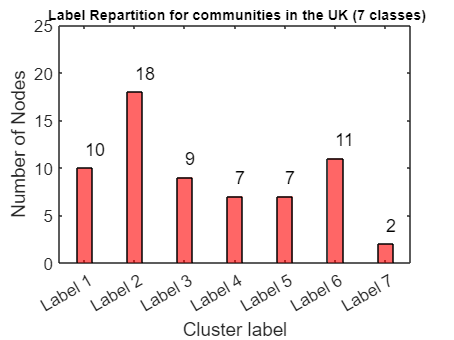

figure,
b=histogram(nb,'BarWidth',0.3,'FaceColor','r');                                                          
xlabel('Cluster label')                                   
ylabel('Number of Nodes') 
ylim([0 25]);
title(' Label Repartition for communities in the UK (7 classes)',FontSize=8)  
y = b.Values;
text(1:b.NumDisplayBins, y+2, string(y));

% PLOT 3 : GRAPH
[indexlabel1UK, indexlabel2UK, indexlabel3UK, LatClass1UK, LongClass1UK, LatClass2UK, LongClass2UK, LatClass3UK, LongClass3UK] = PlotComm(G_UK, UKclusters, UKData);

TableLabel = [G_UK.Nodes, array2table(string(UKclusters))]; % cluster
Table4 = TableLabel(strcmp(TableLabel.Var1, '4'),:); % cluster
Table5 = TableLabel(strcmp(TableLabel.Var1, '5'),:); % cluster
Table6 = TableLabel(strcmp(TableLabel.Var1, '6'),:); % cluster
Table7 = TableLabel(strcmp(TableLabel.Var1, '7'),:); % cluster
listelabel4 = Table4(:,1); % cluster
listelabel5 = Table5(:,1); % cluster
listelabel6 = Table6(:,1); % cluster
listelabel7 = Table7(:,1); % cluster
indexlabel4UK = ind2(table2array(listelabel4), TableLabel); % cluster
indexlabel5UK = ind2(table2array(listelabel5), TableLabel); % cluster
indexlabel6UK = ind2(table2array(listelabel6), TableLabel); % cluster
indexlabel7UK = ind2(table2array(listelabel7), TableLabel); % cluster
listelabel4.Properties.VariableNames(1) = {'id'} % cluster

listelabel4 = 7×1 table
      id   
    _______

    {'CWL'}
    {'VLY'}
    {'LHR'}
    {'ABZ'}
    {'WIC'}
    {'HUY'}
    {'MME'}


listelabel5.Properties.VariableNames(1) = {'id'} % cluster

listelabel5 = 7×1 table
      id   
    _______

    {'BHD'}
    {'LPL'}
    {'DSA'}
    {'STN'}
    {'LDY'}
    {'BOH'}
    {'PIK'}


listelabel6.Properties.VariableNames(1) = {'id'} % cluster

listelabel6 = 11×1 table
      id   
    _______

    {'EDI'}
    {'LGW'}
    {'BHX'}
    {'LBA'}
    {'BLK'}
    {'IOM'}
    {'LTN'}
    {'NQY'}
    {'BFS'}
    {'EMA'}
    {'GLO'}


listelabel7.Properties.VariableNames(1) = {'id'} % cluster

listelabel7 = 2×1 table
      id   
    _______

    {'CEG'}
    {'FZO'}


I4 = innerjoin(listelabel4,UKData); % cluster
I5 = innerjoin(listelabel5,UKData); % cluster
I6 = innerjoin(listelabel6,UKData); % cluster
I7 = innerjoin(listelabel7,UKData); % cluster
LatClass4UK = table2array(I4(:,{'Lat'})); % cluster
LongClass4UK = table2array(I4(:,{'Lon'}));
LatClass5UK = table2array(I5(:,{'Lat'})); % cluster
LongClass5UK = table2array(I5(:,{'Lon'}));
LatClass6UK = table2array(I6(:,{'Lat'})); % cluster
LongClass6UK = table2array(I6(:,{'Lon'}));
LatClass7UK = table2array(I7(:,{'Lat'})); % cluster
LongClass7UK = table2array(I7(:,{'Lon'}));

figure,
h = plot(G_UK)

h =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {1×64 cell}
     EdgeLabel: {}
         XData: [3.5616 4.0091 1.8999 2.5740 2.1413 3.8343 4.8590 1.4332 3.8062 4.4750 3.4225 2.5441 2.5751 3.4966 3.0092 3.7588 3.3258 3.1435 3.1522 2.8183 2.7193 3.2757 3.3147 2.8580 2.7536 2.9652 4.7030 2.6766 3.5217 3.0322 2.8497 1.5716 4.2818 … ]
         YData: [4.2093 4.4779 7.1435 6.0293 6.8836 3.6827 3.0332 7.9259 4.7923 4.5491 4.0932 4.0167 3.2565 4.3316 3.9094 4.0111 4.3472 3.9660 3.6778 3.8248 4.3962 3.5665 3.6683 4.1081 4.8067 4.0551 4.1172 3.7370 3.5301 3.5149 3.3278 3.8725 5.2791 … ]
         ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]

  Show <a href="matla

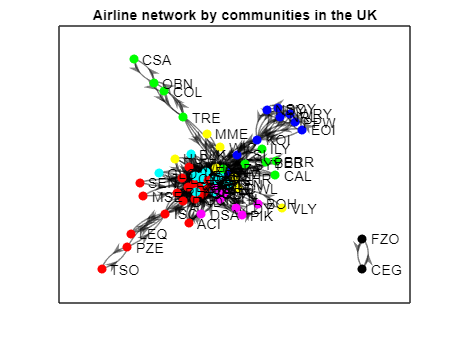

highlight(h,indexlabel1UK,'NodeColor','g')
highlight(h,indexlabel2UK,'NodeColor','r')
highlight(h,indexlabel3UK,'NodeColor','b')
highlight(h,indexlabel4UK,'NodeColor','y')
highlight(h,indexlabel5UK,'NodeColor','m')
highlight(h,indexlabel6UK,'NodeColor','cyan')
highlight(h,indexlabel7UK,'NodeColor','black')
h.EdgeColor = 'black';
title('Airline network by communities in the UK','FontSize',8)

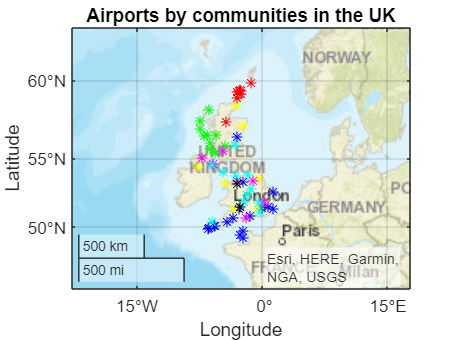


% PLOT 4 : GEOPLOT
figure,
geoplot(LatClass1UK,LongClass1UK,'g*')
hold on
geoplot(LatClass2UK,LongClass2UK,'b*')
geoplot(LatClass3UK,LongClass3UK,'r*')
geoplot(LatClass4UK,LongClass4UK,'y*')
geoplot(LatClass5UK,LongClass5UK,'m*')
geoplot(LatClass6UK,LongClass6UK,'cyan*')
geoplot(LatClass7UK,LongClass7UK,'black*')
geolimits([45 63],[-15 10]) % UK 
geobasemap streets 
hold off
title('Airports by communities in the UK')

Australia

% DETECTION

Comm2Australia=GCModulMax(Adj_Australia) % Modularity method

!!! Graph with isolated communities, no more merging possible !!!


Comm2Australia =      1
     1
     1
     4
     5
     5
     5
     3
     3
     5


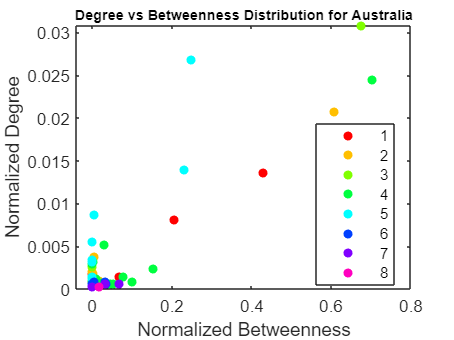

Australiaclusters = Comm2Australia;

% PLOT 1
figure,
gscatter(BC_n_Australia,D_n_Australia,Australiaclusters);    
xlabel('Normalized Betweenness') 
ylabel('Normalized Degree')                          
title('Degree vs Betweenness Distribution for Australia','FontSize',8) 


% PLOT 2 : HISTOGRAM 
nb = categorical(Australiaclusters,[1 2 3 4 5 6 7],{'Label 1','Label 2','Label 3','Label 4','Label 5','Label 6','Label 7'})

nb = 119×1 categorical array
     Label 1 
     Label 1 
     Label 1 
     Label 4 
     Label 5 
     Label 5 
     Label 5 
     Label 3 
     Label 3 
     Label 5 
     Label 4 
     Label 5 
     Label 2 
     Label 4 
     Label 5 
     Label 4 
     Label 3 
     Label 2 
     Label 4 
     Label 1 
     Label 5 
     Label 3 
     Label 2 
     Label 3 
     Label 4 
     Label 5 
     Label 3 
     Label 2 
     Label 3 
     Label 3 


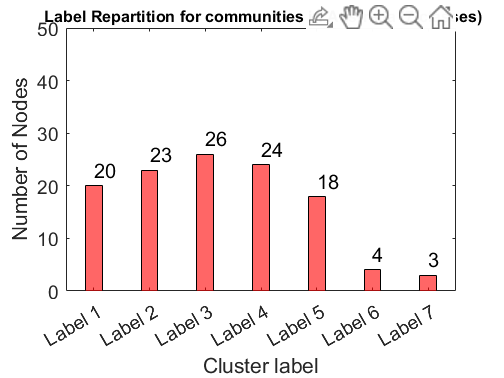

figure,
b=histogram(nb,'BarWidth',0.3,'FaceColor','r');                                                          
xlabel('Cluster label')                                   
ylabel('Number of Nodes')   
ylim([0 50]);
title(' Label Repartition for communities in Australia (7 classes)',FontSize=8)  
y = b.Values;
text(1:b.NumDisplayBins, y+3, string(y));

% PLOT 3 : GRAPH
[indexlabel1Australia, indexlabel2Australia, indexlabel3Australia, LatClass1Australia, LongClass1Australia, LatClass2Australia, LongClass2Australia, LatClass3Australia, LongClass3Australia] = PlotComm(G_Australia, Australiaclusters, AustraliaData);

TableLabel = [G_Australia.Nodes, array2table(string(Australiaclusters))]; % cluster
Table4 = TableLabel(strcmp(TableLabel.Var1, '4'),:); % cluster
Table5 = TableLabel(strcmp(TableLabel.Var1, '5'),:); % cluster
listelabel4 = Table4(:,1); % cluster
listelabel5 = Table5(:,1); % cluster
indexlabel4Australia = ind2(table2array(listelabel4), TableLabel); % cluster
indexlabel5Australia = ind2(table2array(listelabel5), TableLabel); % cluster
listelabel4.Properties.VariableNames(1) = {'id'} % cluster

listelabel4 = 24×1 table
      id   
    _______

    {'BNE'}
    {'TSV'}
    {'ROK'}
    {'LST'}
    {'MKY'}
    {'PPP'}
    {'ISA'}
    {'BEU'}
    {'BVI'}
    {'CTL'}
    {'ULP'}
    {'BQL'}
    {'TWB'}
    {'WNR'}
    {'GLT'}
    {'BDB'}


listelabel5.Properties.VariableNames(1) = {'id'} % cluster

listelabel5 = 18×1 table
      id   
    _______

    {'ADL'}
    {'MEL'}
    {'HBA'}
    {'CBR'}
    {'OOL'}
    {'NTL'}
    {'MQL'}
    {'ABX'}
    {'DPO'}
    {'OLP'}
    {'MGB'}
    {'PLO'}
    {'KNS'}
    {'CED'}
    {'WYA'}
    {'KGC'}


I4 = innerjoin(listelabel4,AustraliaData); % cluster
I5 = innerjoin(listelabel5,AustraliaData); % cluster
LatClass4Australia = table2array(I4(:,{'Lat'})); % cluster
LongClass4Australia = table2array(I4(:,{'Lon'}));
LatClass5Australia = table2array(I5(:,{'Lat'})); % cluster
LongClass5Australia = table2array(I5(:,{'Lon'}));

figure,
h = plot(G_Australia)

h =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 2
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {}
     EdgeLabel: {}
         XData: [-0.0975 -0.1288 -0.1424 0.0855 -0.1200 -0.0838 -0.0485 -0.1172 -0.0820 -0.0815 -0.0133 -0.0826 -0.1731 -0.0107 -0.0496 -0.0347 -0.0735 -0.1891 -0.0291 -0.0601 -0.1057 -0.0452 -0.2210 -0.1172 0.0796 -0.0959 0.0132 -0.0846 0.0132 … ]
         YData: [0.0704 0.0329 -0.0898 0.0254 -0.0928 -0.0548 -0.0287 -0.0791 -0.0579 -0.0512 0.0957 -8.7684e-04 -0.1770 0.0122 -0.0389 -0.0281 -0.0620 -0.2058 0.0055 -0.0451 -0.0686 -0.0361 -0.2378 -0.0791 0.0213 -0.0659 8.8399e-04 -0.0893 … ]
         ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 

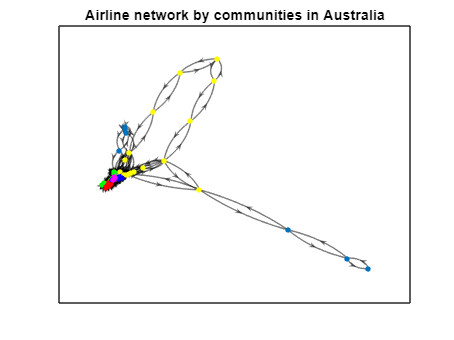

highlight(h,indexlabel1Australia,'NodeColor','g')
highlight(h,indexlabel2Australia,'NodeColor','r')
highlight(h,indexlabel3Australia,'NodeColor','b')
highlight(h,indexlabel4Australia,'NodeColor','y')
highlight(h,indexlabel5Australia,'NodeColor','m')
h.EdgeColor = 'black';
title('Airline network by communities in Australia','FontSize',8)

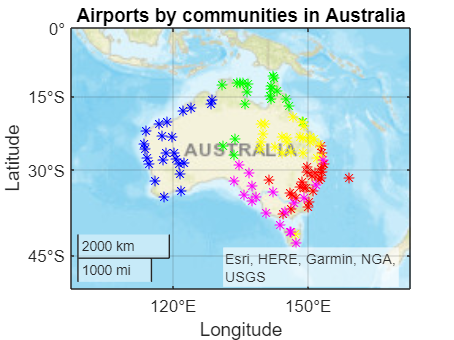



% PLOT 4 : GEOPLOT
figure,
geoplot(LatClass1Australia,LongClass1Australia,'g*')
hold on
geoplot(LatClass2Australia,LongClass2Australia,'b*')
geoplot(LatClass3Australia,LongClass3Australia,'r*')
geoplot(LatClass4Australia,LongClass4Australia,'y*')
geoplot(LatClass5Australia,LongClass5Australia,'m*')
geolimits([-50 0],[120 150]) % Australia
geobasemap streets 
hold off
title('Airports by communities in Australia')

#### Core Periphery Structure 

USA

[ConnectionUSA] = CPS(TableDegreeUSA, G_USA);

figure,
RankNodeUSA = 1:size(ConnectionUSA,1); % Rank of nodes 
RankNodeUSA = reshape(RankNodeUSA,[size(ConnectionUSA,1),1]) 

RankNodeUSA =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


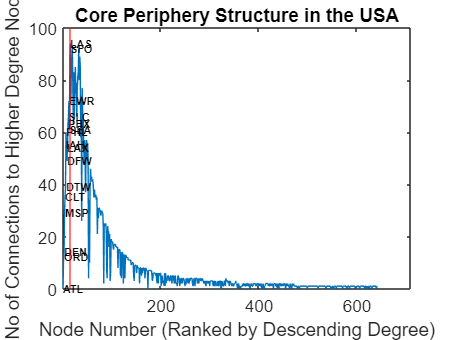

CoNumbUSA = table2array(ConnectionUSA(:,{'GroupCount'}));
[x1USA, y1USA] = max(CoNumbUSA); % y1 = index of the max value 
plot(RankNodeUSA,CoNumbUSA);
hold on 
xline(y1USA,'-r');

xlim([1 710]);
xlabel('Node Number (Ranked by Descending Degree)');
ylabel('No of Connections to Higher Degree Nodes');
title('Core Periphery Structure in the USA');
for i=1:y1USA
    text(RankNodeUSA(i),CoNumbUSA(i), table2array(ConnectionUSA(i,2)),'FontSize',6, 'FontWeight','bold');
end 

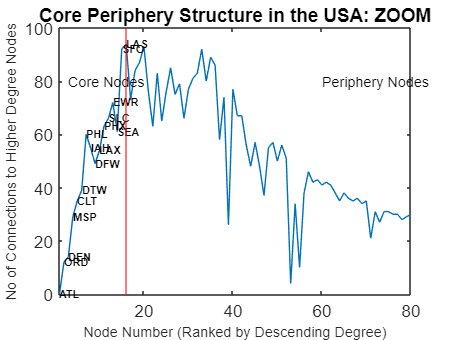

% ZOOM 
figure,
plot(RankNodeUSA,CoNumbUSA);
hold on 
xline(y1USA,'-r');
xlim([1 80]);
%ylim([0 40]);
xlabel('Node Number (Ranked by Descending Degree)','Fontsize',8);
ylabel('No of Connections to Higher Degree Nodes','Fontsize',8);
title('Core Periphery Structure in the USA: ZOOM');
text(60,80,'Periphery Nodes','FontSize',8);
text(3,80,'Core Nodes','FontSize',8);
for i=1:y1USA
    text(RankNodeUSA(i),CoNumbUSA(i), table2array(ConnectionUSA(i,2)),'FontSize',6, 'FontWeight','bold');
end 

China

[ConnectionChina] = CPS(TableDegreeChina, G_China);

figure,
RankNodeChina = 1:size(ConnectionChina,1); % Rank of nodes 
RankNodeChina = reshape(RankNodeChina,[size(ConnectionChina,1),1]) 

RankNodeChina =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


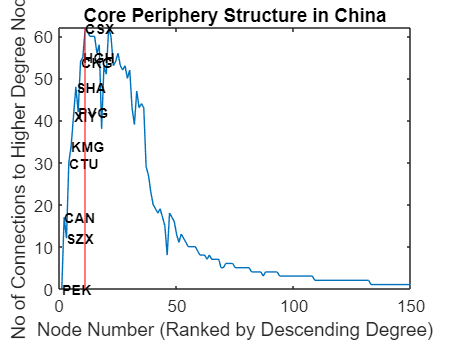

CoNumbChina = table2array(ConnectionChina(:,{'GroupCount'}));
[x1China, y1China] = max(CoNumbChina); % y1 = index of the max value 
plot(RankNodeChina,CoNumbChina);
hold on 
xline(y1China,'-r');

xlabel('Node Number (Ranked by Descending Degree)');
ylabel('No of Connections to Higher Degree Nodes');
title('Core Periphery Structure in China');
for i=1:y1China
    text(RankNodeChina(i),CoNumbChina(i), table2array(ConnectionChina(i,2)),'FontSize', 8, 'FontWeight','bold');
end 

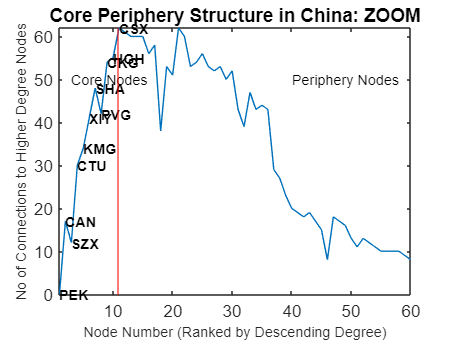

% ZOOM 
figure,
plot(RankNodeChina,CoNumbChina);
hold on 
xline(y1China,'-r');
xlim([1 60]);
%ylim([0 40]);
xlabel('Node Number (Ranked by Descending Degree)','Fontsize',8);
ylabel('No of Connections to Higher Degree Nodes','Fontsize',8);
title('Core Periphery Structure in China: ZOOM');
text(40,50,'Periphery Nodes','FontSize',8);
text(3,50,'Core Nodes','FontSize',8);
for i=1:y1China
    text(RankNodeChina(i),CoNumbChina(i), table2array(ConnectionChina(i,2)),'FontSize', 8, 'FontWeight','bold');
end 

UK

[ConnectionUK] = CPS(TableDegreeUK, G_UK);

figure,
RankNodeUK = 1:size(ConnectionUK,1); % Rank of nodes 
RankNodeUK = reshape(RankNodeUK,[size(ConnectionUK,1),1]) 

RankNodeUK =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


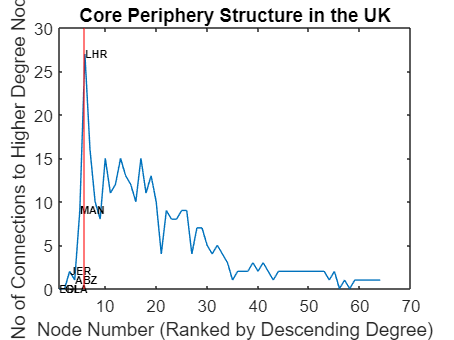

CoNumbUK = table2array(ConnectionUK(:,{'GroupCount'}));
[x1UK, y1UK] = max(CoNumbUK); % y1 = index of the max value 
plot(RankNodeUK,CoNumbUK);
hold on 
xline(y1UK,'-r');

xlim([1 70]);
xlabel('Node Number (Ranked by Descending Degree)');
ylabel('No of Connections to Higher Degree Nodes');
title('Core Periphery Structure in the UK');
for i=1:y1UK
    text(RankNodeUK(i),CoNumbUK(i), table2array(ConnectionUK(i,2)),'FontSize',6, 'FontWeight','bold');
end 

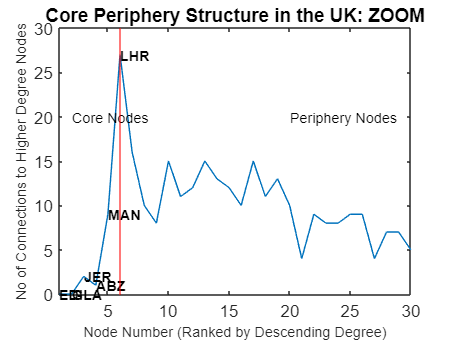

% ZOOM 
figure,
plot(RankNodeUK,CoNumbUK);
hold on 
xline(y1UK,'-r');
xlim([1 30]);
%ylim([0 40]);
xlabel('Node Number (Ranked by Descending Degree)','Fontsize',8);
ylabel('No of Connections to Higher Degree Nodes','Fontsize',8);
title('Core Periphery Structure in the UK: ZOOM');
text(20,20,'Periphery Nodes','FontSize',8);
text(2,20,'Core Nodes','FontSize',8);
for i=1:y1UK
    text(RankNodeUK(i),CoNumbUK(i), table2array(ConnectionUK(i,2)),'FontSize', 8, 'FontWeight','bold');
end 

Australia

[ConnectionAustralia] = CPS(TableDegreeAustralia, G_Australia);

figure,
RankNodeAustralia = 1:size(ConnectionAustralia,1); % Rank of nodes 
RankNodeAustralia = reshape(RankNodeAustralia,[size(ConnectionAustralia,1),1]) 

RankNodeAustralia =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


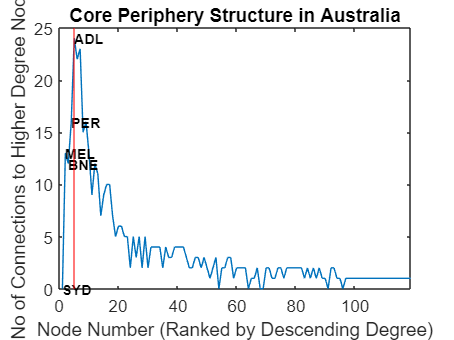

CoNumbAustralia = table2array(ConnectionAustralia(:,{'GroupCount'}));
[x1Australia, y1Australia] = max(CoNumbAustralia); % y1 = index of the max value 
plot(RankNodeAustralia,CoNumbAustralia);
hold on 
xline(y1Australia,'-r');

xlabel('Node Number (Ranked by Descending Degree)');
ylabel('No of Connections to Higher Degree Nodes');
title('Core Periphery Structure in Australia');
for i=1:y1Australia
    text(RankNodeAustralia(i),CoNumbAustralia(i), table2array(ConnectionAustralia(i,2)),'FontSize', 8, 'FontWeight','bold');
end 

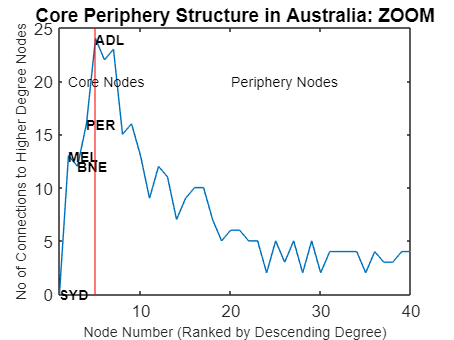

% ZOOM 
figure,
plot(RankNodeAustralia,CoNumbAustralia);
hold on 
xline(y1Australia,'-r');
xlim([1 40]);
%ylim([0 40]);
xlabel('Node Number (Ranked by Descending Degree)','Fontsize',8);
ylabel('No of Connections to Higher Degree Nodes','Fontsize',8);
title('Core Periphery Structure in Australia: ZOOM');
text(20,20,'Periphery Nodes','FontSize',8);
text(2,20,'Core Nodes','FontSize',8);
for i=1:y1Australia
    text(RankNodeAustralia(i),CoNumbAustralia(i), table2array(ConnectionAustralia(i,2)),'FontSize', 8, 'FontWeight','bold');
end 

# FUNCTION PART

Function **ExtractLocation**

function [CountryData, CountryLat, CountryLong] = ExtractLocation (Country, Dataset)
    
    % OUTPUT
    % CountryData : Airports of the country with its position (table)
    % CountryLat : Latitute of all airports of the country (array)
    % CountryLong : Latitute of all airports of the country (array)

    % INPUT
    % Country : Country to study (string) 
    % Dataset : Here GeoData 

    CountryData = Dataset(strcmp(Dataset.country, Country),:);
    CountryLat = table2array(CountryData(:,{'Lat'}));
    CountryLong = table2array(CountryData(:,{'Lon'}));
end

Function** Cleaning**

function [CountrySource, CountryTarget, CountryWeights, lines] = cleaning(Country, Dataset, CountryData)
   
    % OUTPUT
    % CountrySource : Sources IDs (array)
    % CountryTarget : Targets IDs (array)
    % CountryWeights : Weights of the lines (array)
    % NewLines : Lines for the country, with the return (table)

    % INPUT
    % Country : Country to study (string) 
    % Dataset : Here FlightData 
    % CountryData : Extract dataset for the country studied 


    %% STORE SOURCES AND TARGETS FROM FIGHTDATA
    CountryLines = Dataset(strcmp(Dataset.SourceCountry, Country),:); % Lines with Source = Country
    CountryLines = CountryLines(strcmp(CountryLines.TargetCountry, Country),:); % Lines with Source = Country and Target = Country
    
    CountryLines.TimeSeries = string(CountryLines.TimeSeries);
    CountryLines = CountryLines(strcmp(CountryLines.TimeSeries, '01-Jul-2009'),:); % Lines with Source = Country and Target = Country

    CountrySource = table2array(CountryLines(:,{'Source'})); % ID Lines Source
    CountryTarget = table2array(CountryLines(:,{'Target'})); % ID Lines Target
    CountryWeights = table2array(CountryLines(:,{'Weight'})); % ID Lines Weights


    %% SEARCHING FOR SOURCES AND TARGET WHOSE POSITIONS ARE MISSING IN GEODATA
    SourceMissing = ismember(CountrySource, CountryData.id);
    IndexSourceMissing = find(SourceMissing == 0); % index of the ID sources missing 
    TargetMissing = ismember(CountryTarget, CountryData.id);
    IndexTargetMissing = find(TargetMissing==0); % index of the ID targets missing 
    Remove = sort([IndexSourceMissing ; IndexTargetMissing]); % Airports index to remove 
    
    for i = size(Remove,1):-1:1
	CountrySource(Remove(i))=[]; % New CountrySource
    CountryTarget(Remove(i))=[]; % New CountryTarget 
    CountryWeights(Remove(i))=[]; % New CountryWeights 
    end 

    lines = table(CountrySource, CountryTarget, CountryWeights);
    lines = sortrows(lines, [1 2 3]); % Sort by weight  

end 

Function **TableDegree**

function [TableDegreeCountry] = TableDegree(G_Country)

    % OUTPUT
    % TableDegreeCountry : Table with nodes and degrees associated for a country (table)

    % INPUT
    % G_country : Country's graph (graph)

    NodesNamesCountry = G_Country.Nodes;
    NodesDegreeCountry = array2table(indegree(G_Country)+outdegree(G_Country));
    
    TableDegreeCountry = [NodesNamesCountry,NodesDegreeCountry];

end 

Function** PositionsLines**

function [CountryLatSource, CountryLongSource, CountryLatTarget, CountryLongTarget] = PositionsLines(CountrySource, CountryTarget, CountryData)

    % OUTPUT
    % CountryLatSource : Sources IDs Latitudes (array)
    % CountryLongSource : Targets IDs Longitudes (array)
    % CountryLatTarget : Sources IDs Latitudes (array)
    % CountryLongTarget : Targets IDs Longitudes (array)

    % INPUT
    % CountrySource : Sources IDs (array)
    % CountryTarget : Targets IDs (array)
    % CountryData : Extract dataset for the country studied 

    IndexCountrySource = ind(CountrySource, CountryData); % Index of ID Sources in GeoData for the positions
    IndexCountryTarget = ind(CountryTarget, CountryData); % Index of ID Targets in GeoData for the positions
    
    CountryLatSource = table2array(CountryData(IndexCountrySource,{'Lat'})); % Latitude linked with the Source Index
    CountryLongSource = table2array(CountryData(IndexCountrySource,{'Lon'})); % Longitude linked with the Source Index
    CountryLatTarget = table2array(CountryData(IndexCountryTarget,{'Lat'})); % Latitude linked with the Target Index
    CountryLongTarget = table2array(CountryData(IndexCountryTarget,{'Lon'})); % Longitude linked with the Target Index

end 

Function **WDD (Weighted Degree Distribution)**

function [y, rank, weights, rsq, p] = WDD(G, inf, sup)

    % OUTPUT
    % y : Sources IDs (array)
    % rank : Targets IDs (array)
    % weights : Log Weights of the lines sorted (array)
    % rsq : R2 (double)
    % p : (slope, intercept) of the linear regression

    % INPUT
    % G : Graph of the country (graph) 
    % inf : lower bound regression (int)
    % sup : uppper bound regression (int)
    % TableDegree : Degrees associated with each node (table)

    WD = [];
    for n=1:size(G.Nodes,1)
        edges_n = G.Edges([inedges(G,n); outedges(G,n)],:); % edges
        WD = [WD; sum(table2array(edges_n(:,2)))]; % weights
    end 
    
    WD = log10(WD); % log scale
    WD(isinf(WD)) = 1;
    WD = table(WD);
    WD = sortrows(WD,1,'descend');
    weights = table2array(WD(:,1));
    
    rank = 1:size(weights,1); 

    p = polyfit(rank,weights,1); % (slope, intercept) 
    p = polyfit(rank(inf:sup),weights(inf:sup),1); % (slope, intercept) 
    y = p(1)*rank+p(2); % linear regression
    
    % R^2 Calculation
    y = reshape(y,[length(y),1]);
    yresid = weights - y;
    SSresid = sum(yresid.^2);
    SStotal = (length(weights)-1) * var(weights);
    rsq = 1 - SSresid/SStotal;

end 

Function **WDCD (Weighted Degree Cumulative Distribution)**

function [Dwz, C] = WDCD(TableDegree, G)

    % OUTPUT
    % Dwz : Weighted Degree (array)
    % C : Probability computed (array)

    % INPUT
    % G : Graph of the country (graph) 
    % TableDegree : Degrees associated with each node (table)


    Dw = [];
    for n=1:size(G.Nodes,1)
        edges_n = G.Edges([inedges(G,n); outedges(G,n)],:); % edges
        Dw = [Dw; sum(table2array(edges_n(:,2)))]; % weights
    end     
    Dwz = Dw/length(Dw);
        
    Node = table2array(TableDegree(:,2)); % degree
    C = zeros(length(Dwz),1);
    for j=1:length(Dwz)
        for i=1:length(Node)
                if Node(i)>Dwz(j)
                    C(j)=C(j)+1;
                end
        end 
    end     
    C = C/length(Node); % probability y axis 

end 

Function **Distance**

function [distancecountry] = distance_country(G)

    % OUTPUT
    % distancecountry : distances(G) (array)

    % INPUT
    % G : Graph of the country (graph) 

    distancecountry = distances(G);
    
    for i = 1:length(distancecountry)
        for j = 1:length(distancecountry)
            if isinf(distancecountry(i,j))
                distancecountry(i,j)=1000000;
            end 
        end 
    end 
end 

Function **Assortativity**

function   r = assortativity(CIJ)

%   Assortativity coefficient
%
%   r = assortativity(CIJ);
%
%   The assortativity coefficient is a correlation coefficient between the 
%   degrees of all nodes on two opposite ends of a link. A positive 
%   assortativity coefficient indicates that nodes tend to link to other 
%   nodes with the same or similar degree.
%
%   Inputs:     CIJ,        binary directed/undirected connection matrix
%   Outputs:    r,          assortativity

    [id,od,deg] = degrees_dir(CIJ);
    [i,j] = find(CIJ>0);
    K = length(i);
        for k=1:K
            degi(k) = deg(i(k));
            degj(k) = deg(j(k));
        end

    r = (sum(degi.*degj)/K - (sum(0.5*(degi+degj))/K)^2)/(sum(0.5*(degi.^2+degj.^2))/K - (sum(0.5*(degi+degj))/K)^2);
end




function [id,od,deg] = degrees_dir(CIJ)

%   Node degree is the number of links connected to the node. The indegree 
%   is the number of inward links and the outdegree is the number of 
%   outward links.
%
%   Input:      CIJ,    directed (binary/weighted) connection matrix
%
%   Output:     id,     node indegree
%               od,     node outdegree
%               deg,    node degree (indegree + outdegree)
%
%   Notes:  Inputs are assumed to be on the columns of the CIJ matrix.
%           Weight information is discarded.
 
    % ensure CIJ is binary...
    CIJ = double(CIJ~=0);
    
    % compute degrees
    id = sum(CIJ,1);    % indegree = column sum of CIJ
    od = sum(CIJ,2)';   % outdegree = row sum of CIJ
    deg = id+od;        % degree = indegree+outdegree
end

Function **NBND (Normalized Betweenness VS Normalized Degree)**

% Weights integreted in G_simp OK

function [BC, BC_n, D, D_n] = nbnd(G)

    % OUTPUT
    % BC : Betwenness centrality (array)
    % BC_n : Normalized Betwenness centrality (array)
    % D : Degrees (array)
    % D_n : % Normalized Degrees (array)

    % INPUT
    % G : Graph of the country (graph) 

    BC = centrality(G,'betweenness'); % Betwenness centrality
    D = indegree(G)+outdegree(G); % Degrees
    n = numnodes(G); % Number of nodes 
    BC_n = 2*BC./((n-2)*(n-1)); % Normalized Betwenness
    D_n = 2*(D./((n-2)*(n-1))); % Normalized Degree %NodesDegree1

end

Function **GCModulMax (Modularity)**

function VV= GCModulMax(A)
    % Modularity Maximization community detection
    % INPUT
    % A:      Adjacency matrix of graph
    %
    % OUTPUT
    % VV:     N-ny-1 matrix, VV(n) is teh cluster to which node n belongs 
    
    N=length(A);
    W=PermMat(N);                     % permute the graph node labels
    A=W*A*W';
    [VV,Q] = fast_newman(A);
    VV=W'*VV;                         % unpermute the graph node labels
end


function [com,Q] = fast_newman(adj)

% Modularity optimisation based on a greedy agglomerative method
%
% Input
%   - adj: (symmetrical) adjacency matrix
%
% Output
%   - com: communities (listed for each node)
%   - Q  : modularity value of the given partition

    % Set initial communities with one node per community
    cur_com = [1:length(adj)]';
    % Initialise best community to current value
    com = cur_com;
    % Compute initial community matrix
    e = get_community_matrix(adj,com);
    % Lines and columns sum (speed optimisation)
    ls = sum(e,2);
    cs = sum(e,1);
    % Initialise best known and current Q values
    cur_Q = trace(e) - sum(sum(e^2));
    Q = cur_Q;
    % Loop until no more aggregation is possible
    while length(e) > 1
        % Print progress
        %fprintf('Loop %d/%d...',length(adj)-length(e)+1,length(adj));
        %tic
        % Best Q variation
        loop_best_dQ = -inf;
        % For all the pairs of nodes that could be merged
        can_merge = false;
        for i=1:length(e)
            for j=i+1:length(e)
                % If they share edges
                if e(i,j) > 0
                    % Compute the variation in Q
                    dQ = 2 * (e(i,j) - ls(i)*cs(j));
                    % If best variation, then keep track of the pair
                    if dQ > loop_best_dQ
                        loop_best_dQ = dQ;
                        best_pair = [i,j];
                        can_merge = true;
                    end
                end
            end
        end
        if ~can_merge
            disp('!!! Graph with isolated communities, no more merging possible !!!');
            break;
        end
        % Merge the pair of clusters maximising Q
        best_pair = sort(best_pair);
        for i=1:length(cur_com)
            if cur_com(i) == best_pair(2)
                cur_com(i) = best_pair(1);
            elseif cur_com(i) > best_pair(2)
                cur_com(i) = cur_com(i) - 1;
            end    
        end
        % Update community matrix
        % Slow way (for precision comparison)
        %e = get_community_matrix(adj,com);
        % Faster way
        e(best_pair(1),:) = e(best_pair(1),:) + e(best_pair(2),:);
        e(:,best_pair(1)) = e(:,best_pair(1)) + e(:,best_pair(2));
        e(best_pair(2),:) = [];
        e(:,best_pair(2)) = [];
        % Update lines/colums sum
        ls(best_pair(1)) = ls(best_pair(1)) + ls(best_pair(2));
        cs(best_pair(1)) = cs(best_pair(1)) + cs(best_pair(2));
        ls(best_pair(2)) = [];
        cs(best_pair(2)) = [];
        % Update Q value
        cur_Q = cur_Q + loop_best_dQ;
        % Check consistency
        %eqQ = trace(e) - sum(sum(e*e));
        %if Q ~= eqQ
        %    fprintf('Warning: found Q=%d, should be Q=%d. Diff = %d\n',Q,eqQ,abs(Q-eqQ));
        %end
        % If new Q is better, save current partition
        if cur_Q > Q
            Q = cur_Q;
            com = cur_com;
        end
        %fprintf(' completed in %f(s)\n',toc);
    end
end




function [e] = get_community_matrix(adj,com)
% Create the community matrix from a list giving for each node its community
%
% Input
%   - adj: symmetrical (binary or weighted) adjacency matrix
%   - com: community list
%
% Output
%   - e: community adjacency matrix where e(i,j) is half the sum of the
%        weights of edges connecting communities i and j except for the
%        e(i,i) elements which contain the full sum of the weights of edges
%        connecting community i to itself.

    % Number of communities
    nc = length(unique(com));
    % Initialise adjacency matrix list
    e = zeros(nc,nc);
    % Create edges and normalise values by dividing by the sum of all edges
    m = 0;
    for i=1:length(adj)
        for j=i:length(adj)
            if adj(i,j) ~= 0
                ic = com(i);
                jc = com(j);
                if ic == jc
                    e(ic,ic) = e(ic,ic) + adj(i,j);
                else
                    e(ic,jc) = e(ic,jc) + (0.5 * adj(i,j));
                    e(jc,ic) = e(ic,jc);
                end
                m = m + adj(i,j);
            end
        end
    end
    e = e / m;
end

Function **PerMat**

function W=PermMat(N)
% function W=PermMat(N)
% 
% Creates an N-by-N permutation matrix W
%
% INPUT
% N     size of permutation matrix
%
% OUTPUT
% W     the permutation matrix: N-by-N matrix with exactly one 1 in every
%       row and column, all other elements equal to 0
    W=zeros(N,N);
    q=randperm(N);
    for n=1:N; 
	    W(q(n),n)=1; 
    end
end 

Function **PlotComm**

function [indexlabel1, indexlabel2, indexlabel3, LatClass1, LongClass1, LatClass2, LongClass2, LatClass3, LongClass3] = PlotComm(G, clusters, CountryData)
    
    % OUTPUT
    % indexlabel1 (array)
    % indexlabel2 (array)
    % indexlabel3 (array)
    % LatClass1 : Latitude of airports in Class 1 (array)
    % LatClass2 : Latitude of airports in Class 2 (array)
    % LatClass3 : Latitude of airports in Class 3 (array)
    % LongClass1 : Longitude of airports in Class 1 (array)
    % LongClass2 : Longitude of airports in Class 2 (array)
    % LongClass3 : Longitude of airports in Class 3 (array)

    % INPUT
    % G : Graph of the country (graph)
    % clusters : List of clusters for each node (array)
    % CountryData : Extract dataset for the country studied 

    TableLabel = [G.Nodes, array2table(string(clusters))]; 
    Table1 = TableLabel(strcmp(TableLabel.Var1, '1'),:);
    Table2 = TableLabel(strcmp(TableLabel.Var1, '2'),:);
    Table3 = TableLabel(strcmp(TableLabel.Var1, '3'),:);

    listelabel1 = Table1(:,1); 
    listelabel2 = Table2(:,1);
    listelabel3 = Table3(:,1);

    indexlabel1 = ind2(table2array(listelabel1), TableLabel);
    indexlabel2 = ind2(table2array(listelabel2), TableLabel);
    indexlabel3 = ind2(table2array(listelabel3), TableLabel);

    listelabel1.Properties.VariableNames(1) = {'id'};
    listelabel2.Properties.VariableNames(1) = {'id'};
    listelabel3.Properties.VariableNames(1) = {'id'};

    I1 = innerjoin(listelabel1,CountryData);
    I2 = innerjoin(listelabel2,CountryData);
    I3 = innerjoin(listelabel3,CountryData);

    LatClass1 = table2array(I1(:,{'Lat'}));
    LongClass1 = table2array(I1(:,{'Lon'}));
    LatClass2 = table2array(I2(:,{'Lat'}));
    LongClass2 = table2array(I2(:,{'Lon'}));
    LatClass3 = table2array(I3(:,{'Lat'}));
    LongClass3 = table2array(I3(:,{'Lon'}));

end 

Function** CPS (Core Periphery Structure)**

function [Other] = CPS(TableDegree, G)


    % OUTPUT
    % G : Graph of the country (graph)
    % TableDegree : Table with the degrees for each node (table)

    % INPUT
    % Other : number of connections with a higher degree node 

    TableDegree2 = sortrows(TableDegree,2,'descend'); % Sorted by descendent degree
    TableDegree2.Properties.VariableNames(2) = {'Degree'};
    
    E0bis = G.Edges; % Edges for the graph unsimplified 
    E12bis = table2array(E0bis(:,1)); % store just the edges 
    P1 = E12bis(:,1); % source
    P2 = E12bis(:,2); % target
    edges = table(P1,P2); %  Edges Table 
    edges.Properties.VariableNames(1) = {'Name'};
    
    % Join the degree to each node of the lines 
    Y = innerjoin(edges,TableDegree2);
    Y.Properties.VariableNames(3) = {'DegreeName'};
    TableDegree2.Properties.VariableNames(1) = {'P2'};
    Y = innerjoin(Y,TableDegree2);
    Y.Properties.VariableNames(4) = {'DegreeP2'};
    
    % Reference : right columns
    L=zeros(size(Y,1),1);
    DegName = table2array(Y(:,3));
    DegP2 = table2array(Y(:,4));
    for i = 1:length(DegName)
        if DegName(i)>DegP2(i) % connection with a node who has a higher degree
            L(i)=1;
        end
    end
    
    % Remove the lines where the reference node is not connectd with a higher
    % degree node
    for i=length(L):-1:1
        if L(i)==0
            Y([i],:) = [];
        end
    end
    
    % Count the number of connections for those concerned 
    S = groupcounts(Y,'P2'); % Right column : Other concerned nodes
    S = removevars(S,{'Percent'});
    
    
    % Select nodes without connections with high degree node 
    Other = outerjoin(S,TableDegree2);
    Other = removevars(Other,{'P2_S'});
    idx = isnan(Other.GroupCount);
    
    % Update the count of connections for those who haven't to 0
    NewCount = Other.GroupCount;
    for j=1:length(idx)
        if idx(j)==1
            NewCount(j)=0;
        end
    end
    
    Other(:,{'GroupCount'})=array2table(NewCount); % update the column
    Other = sortrows(Other,{'Degree'},'descend');

end

Function **Index** 

function [Index] = ind(IDlist,data)
    Index=[];
    for i = 1:size(IDlist,1)
        Index = [Index;find(strcmp(IDlist(i),data.id))];
    end
end

function [Index] = ind2(IDlist,data)
    Index=[];
    for i = 1:size(IDlist,1)
        Index = [Index;find(strcmp(IDlist(i),data.Name))];
    end
end